# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

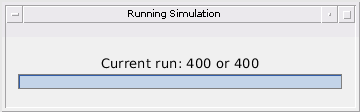

target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    23.1697       NaN       NaN       NaN       NaN
   24.1828       NaN       NaN       NaN       NaN
   25.1947       NaN       NaN       NaN       NaN
   26.1696       NaN       NaN       NaN       NaN
   27.1827       NaN       NaN       NaN       NaN
   28.2151   33.4340       NaN       NaN       NaN
   29.0695       NaN       NaN       NaN       NaN
   30.2901       NaN       NaN       NaN       NaN
   31.2556       NaN       NaN       NaN       NaN
   32.4817   39.2572       NaN       NaN       NaN


actual_ranges =    23.0000   24.0000   25.0001   26.0001   27.0001   28.0002   29.0002   30.0002   31.0003   32.0003


estimated_velocities =   -29.8610       NaN       NaN       NaN       NaN
  -29.8958       NaN       NaN       NaN       NaN
  -29.9237       NaN       NaN       NaN       NaN
  -29.8649       NaN       NaN       NaN       NaN
  -29.8988       NaN       NaN       NaN       NaN
  -29.9066  -29.9741       NaN       NaN       NaN
  -29.9748       NaN       NaN       NaN       NaN
  -29.9141       NaN       NaN       NaN       NaN
  -29.9399       NaN       NaN       NaN       NaN
  -29.9942  -29.9750       NaN       NaN       NaN


actual_velocities =    -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges =     0.1697
    0.1827
    0.1946
    0.1695
    0.1826
    0.2150
    0.0693
    0.2899
    0.2554
    0.4814


percent_error_velocities =     0.1390
    0.1042
    0.0763
    0.1351
    0.1012
    0.0934
    0.0252
    0.0859
    0.0601
    0.0058


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =   104.9571       NaN       NaN       NaN       NaN
  105.0852       NaN       NaN       NaN       NaN
  105.2545       NaN       NaN       NaN       NaN
  105.3863       NaN       NaN       NaN       NaN
  105.3388       NaN       NaN       NaN       NaN
  105.4861  112.0335       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  114.6719  109.1451       NaN       NaN       NaN


actual_ranges =   105.0000  105.1000  105.2000  105.3000  105.4000  105.5000  105.6000  105.7000  105.8000  105.9000


estimated_velocities =    -2.9507       NaN       NaN       NaN       NaN
   -3.0074       NaN       NaN       NaN       NaN
   -3.0000       NaN       NaN       NaN       NaN
   -2.9656       NaN       NaN       NaN       NaN
   -2.9927       NaN       NaN       NaN       NaN
   -3.0045   -2.9724       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -3.0220   -3.0406       NaN       NaN       NaN


actual_velocities =     -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges =     0.0429
    0.0148
    0.0545
    0.0863
    0.0612
    0.0139
         0
         0
         0
         0


percent_error_velocities =     0.0493
    0.0074
    0.0000
    0.0344
    0.0073
    0.0045
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =   103.8802       NaN       NaN       NaN       NaN
  103.8880       NaN       NaN       NaN       NaN
  103.8794       NaN       NaN       NaN       NaN
  103.8764       NaN       NaN       NaN       NaN
  103.8842       NaN       NaN       NaN       NaN
  104.6892  110.5892       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  109.0550       NaN       NaN       NaN       NaN
  108.3899       NaN       NaN       NaN       NaN
  107.4241  112.8899       NaN       NaN       NaN


actual_ranges =    104   104   104   104   104   104   104   104   104   104


estimated_velocities =    -0.0015       NaN       NaN       NaN       NaN
   -0.0069       NaN       NaN       NaN       NaN
   -0.0005       NaN       NaN       NaN       NaN
   -0.0020       NaN       NaN       NaN       NaN
   -0.0031       NaN       NaN       NaN       NaN
   -0.0079    0.0123       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0102       NaN       NaN       NaN       NaN
   -0.0143       NaN       NaN       NaN       NaN
   -0.0036    0.0092       NaN       NaN       NaN


actual_velocities =      0     0     0     0     0     0     0     0     0     0


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges =     0.1198
    0.1120
    0.1206
    0.1236
    0.1158
         0
         0
         0
         0
         0


percent_error_velocities =     0.0015
    0.0069
    0.0005
    0.0020
    0.0031
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    29.8208       NaN       NaN       NaN       NaN
   28.6606       NaN       NaN       NaN       NaN
   27.4923       NaN       NaN       NaN       NaN
   26.3518       NaN       NaN       NaN       NaN
   25.2186       NaN       NaN       NaN       NaN
   31.5012       NaN       NaN       NaN       NaN
   22.7360       NaN       NaN       NaN       NaN
   21.5470       NaN       NaN       NaN       NaN
   20.3938       NaN       NaN       NaN       NaN
   19.2735   28.5404       NaN       NaN       NaN


actual_ranges =    30.0000   28.8333   27.6666   26.4999   25.3332   24.1665   22.9998   21.8331   20.6664   19.4997


estimated_velocities =    34.8145       NaN       NaN       NaN       NaN
   34.8461       NaN       NaN       NaN       NaN
   34.9202       NaN       NaN       NaN       NaN
   34.9062       NaN       NaN       NaN       NaN
   34.8947       NaN       NaN       NaN       NaN
   35.0249       NaN       NaN       NaN       NaN
   34.7737       NaN       NaN       NaN       NaN
   34.7731       NaN       NaN       NaN       NaN
   34.9154       NaN       NaN       NaN       NaN
   34.9050   35.0092       NaN       NaN       NaN


actual_velocities =     35    35    35    35    35    35    35    35    35    35


detected =      1     1     1     1     1     0     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges =     0.1792
    0.1727
    0.1743
    0.1480
    0.1146
         0
    0.2638
    0.2861
    0.2726
    0.2261


percent_error_velocities =     0.1855
    0.1539
    0.0798
    0.0938
    0.1053
         0
    0.2263
    0.2269
    0.0846
    0.0950


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    42.9726       NaN       NaN       NaN       NaN
   42.8158       NaN       NaN       NaN       NaN
   42.6522       NaN       NaN       NaN       NaN
   42.5174       NaN       NaN       NaN       NaN
   42.3805       NaN       NaN       NaN       NaN
   48.8940   43.0057       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   42.0001   50.2681   44.2871       NaN       NaN


actual_ranges =    43.0000   42.8667   42.7333   42.6000   42.4666   42.3333   42.2000   42.0666   41.9333   41.8000


estimated_velocities =     3.9754       NaN       NaN       NaN       NaN
    3.9746       NaN       NaN       NaN       NaN
    3.9764       NaN       NaN       NaN       NaN
    3.9643       NaN       NaN       NaN       NaN
    3.9647       NaN       NaN       NaN       NaN
    3.9898    3.9609       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.9750    3.9906    3.9750       NaN       NaN


actual_velocities =      4     4     4     4     4     4     4     4     4     4


detected =      1     1     1     1     1     0     0     0     0     1


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     1


false_positives =      0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges =     0.0274
    0.0509
    0.0811
    0.0826
    0.0861
         0
         0
         0
         0
    0.2001


percent_error_velocities =     0.0246
    0.0254
    0.0236
    0.0357
    0.0353
         0
         0
         0
         0
    0.0250


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    54.9517       NaN       NaN       NaN       NaN
   53.7632       NaN       NaN       NaN       NaN
   52.7578       NaN       NaN       NaN       NaN
   51.7956       NaN       NaN       NaN       NaN
   50.7843       NaN       NaN       NaN       NaN
   57.3028   51.2862       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   51.1800       NaN       NaN       NaN       NaN
   55.0368   49.2101       NaN       NaN       NaN


actual_ranges =    55.0000   53.9666   52.9333   51.8999   50.8665   49.8332   48.7998   47.7664   46.7331   45.6997


estimated_velocities =    30.9310       NaN       NaN       NaN       NaN
   30.8976       NaN       NaN       NaN       NaN
   30.9511       NaN       NaN       NaN       NaN
   30.9458       NaN       NaN       NaN       NaN
   30.8702       NaN       NaN       NaN       NaN
   31.0051   30.9866       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   30.9671       NaN       NaN       NaN       NaN
   31.0004   30.9885       NaN       NaN       NaN


actual_velocities =     31    31    31    31    31    31    31    31    31    31


detected =      1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0483
    0.2035
    0.1754
    0.1043
    0.0822
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0690
    0.1024
    0.0489
    0.0542
    0.1298
         0
         0
         0
         0
         0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   43.1979       NaN       NaN       NaN       NaN
   44.1569       NaN       NaN       NaN       NaN
   45.1584       NaN       NaN       NaN       NaN
   46.2101       NaN       NaN       NaN       NaN
   47.3252       NaN       NaN       NaN       NaN
   48.2481   53.6556       NaN       NaN       NaN
   49.4845       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   52.3697   54.0502   59.8414       NaN       NaN


actual_ranges = 1×10
   43.0000   44.0334   45.0667   46.1001   47.1335   48.1668   49.2002   50.2336   51.2669   52.3003


estimated_velocities = 10×5
  -30.9423       NaN       NaN       NaN       NaN
  -30.9440       NaN       NaN       NaN       NaN
  -30.9153       NaN       NaN       NaN       NaN
  -30.7787       NaN       NaN       NaN       NaN
  -30.9171       NaN       NaN       NaN       NaN
  -30.9842  -30.9776       NaN       NaN       NaN
  -30.9756       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -31.0088  -31.0017  -30.9882       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1979
    0.1235
    0.0917
    0.1100
    0.1917
    0.0813
    0.2843
         0
         0
    0.0694


percent_error_velocities = 10×1
    0.0577
    0.0560
    0.0847
    0.2213
    0.0829
    0.0158
    0.0244
         0
         0
    0.0088


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   99.9124       NaN       NaN       NaN       NaN
   98.5994       NaN       NaN       NaN       NaN
   97.2785       NaN       NaN       NaN       NaN
   96.1728       NaN       NaN       NaN       NaN
   94.8744       NaN       NaN       NaN       NaN
  101.6727   95.6254       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   95.3943       NaN       NaN       NaN       NaN
   98.8508   93.4950       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000   98.7666   97.5333   96.2999   95.0665   93.8331   92.5998   91.3664   90.1330   88.8996


estimated_velocities = 10×5
   36.9301       NaN       NaN       NaN       NaN
   36.9283       NaN       NaN       NaN       NaN
   36.9110       NaN       NaN       NaN       NaN
   36.8821       NaN       NaN       NaN       NaN
   36.9345       NaN       NaN       NaN       NaN
   37.0033   36.9839       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   36.9661       NaN       NaN       NaN       NaN
   36.9770   36.9632       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0876
    0.1672
    0.2548
    0.1271
    0.1921
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0699
    0.0717
    0.0890
    0.1179
    0.0655
         0
         0
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   19.9442       NaN       NaN       NaN       NaN
   19.1003       NaN       NaN       NaN       NaN
   18.2332       NaN       NaN       NaN       NaN
   15.3869   17.3653       NaN       NaN       NaN
   16.4989       NaN       NaN       NaN       NaN
   23.0400   16.9558       NaN       NaN       NaN
   14.8447       NaN       NaN       NaN       NaN
   14.1696       NaN       NaN       NaN       NaN
   13.2818       NaN       NaN       NaN       NaN
   12.3518   21.1484   14.8494       NaN       NaN


actual_ranges = 1×10
   20.0000   19.1666   18.3333   17.4999   16.6666   15.8332   14.9998   14.1665   13.3331   12.4998


estimated_velocities = 10×5
   24.8598       NaN       NaN       NaN       NaN
   24.9286       NaN       NaN       NaN       NaN
   24.9550       NaN       NaN       NaN       NaN
   12.9806   24.9605       NaN       NaN       NaN
   24.9485       NaN       NaN       NaN       NaN
   24.9919   24.9735       NaN       NaN       NaN
   24.8012       NaN       NaN       NaN       NaN
   24.9438       NaN       NaN       NaN       NaN
   24.9565       NaN       NaN       NaN       NaN
   24.9451   24.9928   24.9796       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0558
    0.0664
    0.1001
    0.1347
    0.1677
         0
    0.1552
    0.0031
    0.0514
    0.1480


percent_error_velocities = 10×1
    0.1402
    0.0714
    0.0450
    0.0395
    0.0515
         0
    0.1988
    0.0562
    0.0435
    0.0549


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  126.1146       NaN       NaN       NaN       NaN
  126.7934       NaN       NaN       NaN       NaN
  127.6902       NaN       NaN       NaN       NaN
  128.4088       NaN       NaN       NaN       NaN
  129.1117       NaN       NaN       NaN       NaN
  130.0211  135.7729       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  134.8010  140.7258       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  126.7667  127.5334  128.3001  129.0668  129.8335  130.6001  131.3668  132.1335  132.9002


estimated_velocities = 10×5
  -22.9397       NaN       NaN       NaN       NaN
  -22.9525       NaN       NaN       NaN       NaN
  -22.8836       NaN       NaN       NaN       NaN
  -22.9477       NaN       NaN       NaN       NaN
  -22.8638       NaN       NaN       NaN       NaN
  -22.9893  -22.9662       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.0110  -22.9887       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1146
    0.0267
    0.1568
    0.1088
    0.0449
    0.1876
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0603
    0.0475
    0.1164
    0.0523
    0.1362
    0.0107
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   68.9412       NaN       NaN       NaN       NaN
   68.3436       NaN       NaN       NaN       NaN
   67.8421       NaN       NaN       NaN       NaN
   67.3905       NaN       NaN       NaN       NaN
   66.7975       NaN       NaN       NaN       NaN
   73.4064       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   73.2971   67.6689       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   68.4666   67.9333   67.3999   66.8666   66.3332   65.7999   65.2665   64.7332   64.1998


estimated_velocities = 10×5
   15.9766       NaN       NaN       NaN       NaN
   15.9674       NaN       NaN       NaN       NaN
   15.8212       NaN       NaN       NaN       NaN
   15.9655       NaN       NaN       NaN       NaN
   15.9708       NaN       NaN       NaN       NaN
   16.0168       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.9905   15.9658       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0588
    0.1231
    0.0912
    0.0095
    0.0691
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0234
    0.0326
    0.1788
    0.0345
    0.0292
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   37.9414       NaN       NaN       NaN       NaN
   38.2688       NaN       NaN       NaN       NaN
   38.5551       NaN       NaN       NaN       NaN
   38.8575       NaN       NaN       NaN       NaN
   39.1690       NaN       NaN       NaN       NaN
   45.4610   39.7194       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   40.2901       NaN       NaN       NaN       NaN
   40.5495   48.4266   42.4290       NaN       NaN


actual_ranges = 1×10
   38.0000   38.2667   38.5334   38.8000   39.0667   39.3334   39.6001   39.8667   40.1334   40.4001


estimated_velocities = 10×5
   -8.0031       NaN       NaN       NaN       NaN
   -7.9998       NaN       NaN       NaN       NaN
   -8.0086       NaN       NaN       NaN       NaN
   -8.0014       NaN       NaN       NaN       NaN
   -8.0038       NaN       NaN       NaN       NaN
   -8.0017   -8.0215       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -8.0132       NaN       NaN       NaN       NaN
   -8.0380   -8.0154   -8.0281       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0586
    0.0021
    0.0217
    0.0574
    0.1023
    0.3861
         0
         0
    0.1567
    0.1495


percent_error_velocities = 10×1
    0.0031
    0.0002
    0.0086
    0.0014
    0.0038
    0.0215
         0
         0
    0.0132
    0.0380


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   56.1745       NaN       NaN       NaN       NaN
   57.2475       NaN       NaN       NaN       NaN
   58.2614       NaN       NaN       NaN       NaN
   59.4640       NaN       NaN       NaN       NaN
   60.5677       NaN       NaN       NaN       NaN
   66.9602   61.1914       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   66.0547   73.6315   67.9313       NaN       NaN


actual_ranges = 1×10
   56.0000   57.1000   58.2001   59.3001   60.4001   61.5002   62.6002   63.7002   64.8003   65.9003


estimated_velocities = 10×5
  -32.9177       NaN       NaN       NaN       NaN
  -32.7306       NaN       NaN       NaN       NaN
  -32.9389       NaN       NaN       NaN       NaN
  -32.9516       NaN       NaN       NaN       NaN
  -32.8551       NaN       NaN       NaN       NaN
  -33.0071  -33.0249       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0301  -33.0123  -33.0216       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1745
    0.1474
    0.0613
    0.1639
    0.1675
    0.3088
         0
         0
         0
    0.1544


percent_error_velocities = 10×1
    0.0823
    0.2694
    0.0611
    0.0484
    0.1449
    0.0249
         0
         0
         0
    0.0301


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   34.9556       NaN       NaN       NaN       NaN
   34.7793       NaN       NaN       NaN       NaN
   34.8801       NaN       NaN       NaN       NaN
   34.6925       NaN       NaN       NaN       NaN
   34.5040       NaN       NaN       NaN       NaN
   35.2242   40.9857       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.3109       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   42.5080       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   34.9000   34.8000   34.7000   34.6000   34.5000   34.4000   34.3000   34.2000   34.1000


estimated_velocities = 10×5
    3.0029       NaN       NaN       NaN       NaN
    3.0001       NaN       NaN       NaN       NaN
    2.9958       NaN       NaN       NaN       NaN
    3.0015       NaN       NaN       NaN       NaN
    2.9978       NaN       NaN       NaN       NaN
    2.9787    3.0266       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    2.9886       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.0068       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     0     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0444
    0.1207
    0.0801
    0.0075
    0.0960
         0
         0
    0.0109
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0001
    0.0042
    0.0015
    0.0022
         0
         0
    0.0114
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   86.9259       NaN       NaN       NaN       NaN
   86.6737       NaN       NaN       NaN       NaN
   86.2312       NaN       NaN       NaN       NaN
   85.7445       NaN       NaN       NaN       NaN
   85.5086       NaN       NaN       NaN       NaN
   92.0595   86.0737       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   93.0932   87.7707       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.6333   86.2666   85.9000   85.5333   85.1666   84.7999   84.4333   84.0666   83.6999


estimated_velocities = 10×5
   10.9718       NaN       NaN       NaN       NaN
   10.9407       NaN       NaN       NaN       NaN
   10.9711       NaN       NaN       NaN       NaN
   10.9605       NaN       NaN       NaN       NaN
   10.9577       NaN       NaN       NaN       NaN
   11.0045   10.9786       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   11.0027   10.9861       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0741
    0.0404
    0.0354
    0.1555
    0.0247
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0282
    0.0593
    0.0289
    0.0395
    0.0423
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   16.9730       NaN       NaN       NaN       NaN
   16.9731       NaN       NaN       NaN       NaN
   16.9731       NaN       NaN       NaN       NaN
   16.9730       NaN       NaN       NaN       NaN
   16.9730       NaN       NaN       NaN       NaN
   16.9958   23.4919       NaN       NaN       NaN
   16.9379       NaN       NaN       NaN       NaN
   16.9057       NaN       NaN       NaN       NaN
   17.0714       NaN       NaN       NaN       NaN
   19.3786   16.9404   24.9298       NaN       NaN


actual_ranges = 1×10
    17    17    17    17    17    17    17    17    17    17


estimated_velocities = 10×5
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
    0.0001       NaN       NaN       NaN       NaN
   -0.0024    0.0123       NaN       NaN       NaN
    0.0001       NaN       NaN       NaN       NaN
    0.0012       NaN       NaN       NaN       NaN
   -0.0016       NaN       NaN       NaN       NaN
   -0.0140   -0.0011    0.0003       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0270
    0.0269
    0.0269
    0.0270
    0.0270
    0.0042
    0.0621
    0.0943
    0.0714
    0.0596


percent_error_velocities = 10×1
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0024
    0.0001
    0.0012
    0.0016
    0.0011


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   20.9804       NaN       NaN       NaN       NaN
   21.1673       NaN       NaN       NaN       NaN
   21.1402       NaN       NaN       NaN       NaN
   21.2918       NaN       NaN       NaN       NaN
   21.2685       NaN       NaN       NaN       NaN
   21.2772   27.7585       NaN       NaN       NaN
   21.3850       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.4690       NaN       NaN       NaN       NaN
   29.4319   23.1676       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.0667   21.1333   21.2000   21.2667   21.3333   21.4000   21.4667   21.5334   21.6000


estimated_velocities = 10×5
   -2.0152       NaN       NaN       NaN       NaN
   -2.0099       NaN       NaN       NaN       NaN
   -2.0151       NaN       NaN       NaN       NaN
   -1.9924       NaN       NaN       NaN       NaN
   -2.0154       NaN       NaN       NaN       NaN
   -2.0308   -1.9991       NaN       NaN       NaN
   -2.0143       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0136       NaN       NaN       NaN       NaN
   -2.0105   -2.0300       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0196
    0.1007
    0.0069
    0.0918
    0.0018
    0.0561
    0.0150
         0
    0.0643
         0


percent_error_velocities = 10×1
    0.0152
    0.0099
    0.0151
    0.0076
    0.0154
    0.0308
    0.0143
         0
    0.0136
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  128.1061       NaN       NaN       NaN       NaN
  129.0896       NaN       NaN       NaN       NaN
  129.9539       NaN       NaN       NaN       NaN
  130.9826       NaN       NaN       NaN       NaN
  131.8372       NaN       NaN       NaN       NaN
  138.6858  132.7924       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  144.1303  138.1567       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  128.9334  129.8667  130.8001  131.7335  132.6668  133.6002  134.5335  135.4669  136.4003


estimated_velocities = 10×5
  -27.9612       NaN       NaN       NaN       NaN
  -27.8214       NaN       NaN       NaN       NaN
  -27.9609       NaN       NaN       NaN       NaN
  -27.8850       NaN       NaN       NaN       NaN
  -27.8926       NaN       NaN       NaN       NaN
  -28.0031  -28.0174       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.0099  -28.0271       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1061
    0.1563
    0.0872
    0.1825
    0.1038
    0.1255
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0388
    0.1786
    0.0391
    0.1150
    0.1074
    0.0174
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  104.9153       NaN       NaN       NaN       NaN
  103.9989       NaN       NaN       NaN       NaN
  102.9893       NaN       NaN       NaN       NaN
  102.1761       NaN       NaN       NaN       NaN
  101.3181       NaN       NaN       NaN       NaN
  101.9805  108.0788       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  101.2150  106.6321       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.1000  103.1999  102.2999  101.3999  100.4999   99.5998   98.6998   97.7998   96.8997


estimated_velocities = 10×5
   26.9641       NaN       NaN       NaN       NaN
   26.8306       NaN       NaN       NaN       NaN
   26.9621       NaN       NaN       NaN       NaN
   26.9759       NaN       NaN       NaN       NaN
   26.8306       NaN       NaN       NaN       NaN
   27.0057   27.0218       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.0025   27.0150       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0847
    0.1011
    0.2106
    0.1238
    0.0817
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0359
    0.1694
    0.0379
    0.0241
    0.1694
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  142.1194       NaN       NaN       NaN       NaN
  142.8741       NaN       NaN       NaN       NaN
  143.3156       NaN       NaN       NaN       NaN
  144.1040       NaN       NaN       NaN       NaN
  144.9096       NaN       NaN       NaN       NaN
  145.2489  151.4256       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  150.0350  155.9656       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  142.6667  143.3334  144.0001  144.6668  145.3334  146.0001  146.6668  147.3335  148.0002


estimated_velocities = 10×5
  -19.9869       NaN       NaN       NaN       NaN
  -19.9042       NaN       NaN       NaN       NaN
  -19.9964       NaN       NaN       NaN       NaN
  -19.9862       NaN       NaN       NaN       NaN
  -19.9946       NaN       NaN       NaN       NaN
  -20.0223  -20.0067       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.0141  -20.0006       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1194
    0.2074
    0.0178
    0.1039
    0.2428
    0.0845
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0958
    0.0036
    0.0138
    0.0054
    0.0223
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.8976       NaN       NaN       NaN       NaN
  109.0100       NaN       NaN       NaN       NaN
  107.9723       NaN       NaN       NaN       NaN
  107.1944       NaN       NaN       NaN       NaN
  106.3894       NaN       NaN       NaN       NaN
  107.0195  112.8798       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  105.9741  111.5185       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  109.1000  108.1999  107.2999  106.3999  105.4999  104.5998  103.6998  102.7998  101.8997


estimated_velocities = 10×5
   26.9684       NaN       NaN       NaN       NaN
   26.7773       NaN       NaN       NaN       NaN
   26.9805       NaN       NaN       NaN       NaN
   26.9875       NaN       NaN       NaN       NaN
   26.9676       NaN       NaN       NaN       NaN
   27.0015   27.0227       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.0018   27.0147       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1024
    0.0899
    0.2276
    0.1055
    0.0105
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0316
    0.2227
    0.0195
    0.0125
    0.0324
         0
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  104.1460       NaN       NaN       NaN       NaN
  104.5575       NaN       NaN       NaN       NaN
  104.9857       NaN       NaN       NaN       NaN
  105.4090       NaN       NaN       NaN       NaN
  105.8308       NaN       NaN       NaN       NaN
  106.2956  112.3970       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  111.2398       NaN       NaN       NaN       NaN
  116.4468  110.8385  116.3696       NaN       NaN


actual_ranges = 1×10
  104.0000  104.4333  104.8667  105.3000  105.7334  106.1667  106.6001  107.0334  107.4668  107.9001


estimated_velocities = 10×5
  -12.9494       NaN       NaN       NaN       NaN
  -12.9516       NaN       NaN       NaN       NaN
  -12.9747       NaN       NaN       NaN       NaN
  -12.9711       NaN       NaN       NaN       NaN
  -12.9901       NaN       NaN       NaN       NaN
  -13.0062  -12.9939       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -13.0219       NaN       NaN       NaN       NaN
   14.0753  -13.0119  -12.9958       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.1460
    0.1242
    0.1190
    0.1090
    0.0974
    0.1289
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0506
    0.0484
    0.0253
    0.0289
    0.0099
    0.0062
         0
         0
         0
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   84.9372       NaN       NaN       NaN       NaN
   84.4704       NaN       NaN       NaN       NaN
   84.0462       NaN       NaN       NaN       NaN
   83.8265       NaN       NaN       NaN       NaN
   83.3656       NaN       NaN       NaN       NaN
   90.0055   83.0761       NaN       NaN       NaN
   87.0433       NaN       NaN       NaN       NaN
   87.7180       NaN       NaN       NaN       NaN
   86.6097       NaN       NaN       NaN       NaN
   90.7583   85.3875       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   84.6000   84.2000   83.8000   83.3999   82.9999   82.5999   82.1999   81.7999   81.3999


estimated_velocities = 10×5
   11.9720       NaN       NaN       NaN       NaN
   11.9793       NaN       NaN       NaN       NaN
   11.8736       NaN       NaN       NaN       NaN
   11.9431       NaN       NaN       NaN       NaN
   11.9734       NaN       NaN       NaN       NaN
   12.0004   11.9784       NaN       NaN       NaN
   11.9891       NaN       NaN       NaN       NaN
   11.9684       NaN       NaN       NaN       NaN
   11.9777       NaN       NaN       NaN       NaN
   11.9840   11.9750       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0628
    0.1296
    0.1538
    0.0266
    0.0343
    0.0761
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0280
    0.0207
    0.1264
    0.0569
    0.0266
    0.0216
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.1046       NaN       NaN       NaN       NaN
  137.2510       NaN       NaN       NaN       NaN
  137.3705       NaN       NaN       NaN       NaN
  137.4865       NaN       NaN       NaN       NaN
  137.6299       NaN       NaN       NaN       NaN
  138.5679  144.4843       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  140.9724  147.0088       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.1667  137.3333  137.5000  137.6667  137.8334  138.0000  138.1667  138.3334  138.5000


estimated_velocities = 10×5
   -4.9676       NaN       NaN       NaN       NaN
   -4.9800       NaN       NaN       NaN       NaN
   -4.9877       NaN       NaN       NaN       NaN
   -4.9757       NaN       NaN       NaN       NaN
   -4.9778       NaN       NaN       NaN       NaN
   -4.9993   -4.9793       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.9949   -4.9813       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1046
    0.0843
    0.0371
    0.0136
    0.0368
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0324
    0.0200
    0.0123
    0.0243
    0.0222
         0
         0
         0
         0
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  118.8716       NaN       NaN       NaN       NaN
  118.4801       NaN       NaN       NaN       NaN
  118.1366       NaN       NaN       NaN       NaN
  117.4002       NaN       NaN       NaN       NaN
  117.0549       NaN       NaN       NaN       NaN
  117.9079  123.7827       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  117.9763  123.8770       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  118.5333  118.0666  117.6000  117.1333  116.6666  116.1999  115.7332  115.2665  114.7999


estimated_velocities = 10×5
   13.9948       NaN       NaN       NaN       NaN
   14.0033       NaN       NaN       NaN       NaN
   13.9941       NaN       NaN       NaN       NaN
   13.9883       NaN       NaN       NaN       NaN
   13.9990       NaN       NaN       NaN       NaN
   14.0102   14.0292       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   14.0008   14.0108       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1284
    0.0532
    0.0700
    0.1997
    0.0784
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0052
    0.0033
    0.0059
    0.0117
    0.0010
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   97.8938       NaN       NaN       NaN       NaN
   97.7933       NaN       NaN       NaN       NaN
   97.6529       NaN       NaN       NaN       NaN
   97.5404       NaN       NaN       NaN       NaN
   97.4164       NaN       NaN       NaN       NaN
  103.9392   97.9797       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.7475       NaN       NaN       NaN       NaN
  105.6189  100.2180       NaN       NaN       NaN


actual_ranges = 1×10
   98.0000   97.8333   97.6667   97.5000   97.3333   97.1666   97.0000   96.8333   96.6666   96.5000


estimated_velocities = 10×5
    4.9784       NaN       NaN       NaN       NaN
    4.9792       NaN       NaN       NaN       NaN
    4.9841       NaN       NaN       NaN       NaN
    4.9723       NaN       NaN       NaN       NaN
    4.9682       NaN       NaN       NaN       NaN
    4.9930    4.9709       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    4.9733       NaN       NaN       NaN       NaN
    4.9767    4.9613       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.1062
    0.0401
    0.0137
    0.0405
    0.0831
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0216
    0.0208
    0.0159
    0.0277
    0.0318
         0
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   32.9726       NaN       NaN       NaN       NaN
   32.6355       NaN       NaN       NaN       NaN
   32.5661       NaN       NaN       NaN       NaN
   32.2572       NaN       NaN       NaN       NaN
   31.9526       NaN       NaN       NaN       NaN
   31.9513   38.3932       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.2365       NaN       NaN       NaN       NaN
   30.8671   33.1295   39.2445       NaN       NaN


actual_ranges = 1×10
   33.0000   32.7667   32.5333   32.3000   32.0666   31.8333   31.6000   31.3666   31.1333   30.8999


estimated_velocities = 10×5
    7.0009       NaN       NaN       NaN       NaN
    6.9987       NaN       NaN       NaN       NaN
    6.9904       NaN       NaN       NaN       NaN
    6.9972       NaN       NaN       NaN       NaN
    6.9795       NaN       NaN       NaN       NaN
    6.9927    7.0212       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9996       NaN       NaN       NaN       NaN
    7.0026    6.9999    7.0100       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0274
    0.1311
    0.0328
    0.0428
    0.1141
    0.1180
         0
         0
    0.1032
    0.0329


percent_error_velocities = 10×1
    0.0009
    0.0013
    0.0096
    0.0028
    0.0205
    0.0073
         0
         0
    0.0004
    0.0026


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   19.9357       NaN       NaN       NaN       NaN
   19.1789       NaN       NaN       NaN       NaN
   18.4047       NaN       NaN       NaN       NaN
   17.6660       NaN       NaN       NaN       NaN
   16.9454       NaN       NaN       NaN       NaN
   16.1619   23.4533       NaN       NaN       NaN
   15.4594       NaN       NaN       NaN       NaN
   14.8731       NaN       NaN       NaN       NaN
   14.1815       NaN       NaN       NaN       NaN
   15.7385   13.2179   21.9142       NaN       NaN


actual_ranges = 1×10
   20.0000   19.2666   18.5333   17.7999   17.0666   16.3332   15.5999   14.8665   14.1331   13.3998


estimated_velocities = 10×5
   21.8615       NaN       NaN       NaN       NaN
   21.8355       NaN       NaN       NaN       NaN
   21.8543       NaN       NaN       NaN       NaN
   21.8793       NaN       NaN       NaN       NaN
   21.9627       NaN       NaN       NaN       NaN
   21.9571   22.0166       NaN       NaN       NaN
   21.9222       NaN       NaN       NaN       NaN
   21.8658       NaN       NaN       NaN       NaN
   21.8408       NaN       NaN       NaN       NaN
   22.0094   21.8058   22.0303       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0643
    0.0878
    0.1286
    0.1339
    0.1212
    0.1714
    0.1404
    0.0066
    0.0483
    0.1819


percent_error_velocities = 10×1
    0.1385
    0.1645
    0.1457
    0.1207
    0.0373
    0.0429
    0.0778
    0.1342
    0.1592
    0.1942


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   57.9598       NaN       NaN       NaN       NaN
   57.5375       NaN       NaN       NaN       NaN
   57.1121       NaN       NaN       NaN       NaN
   56.6881       NaN       NaN       NaN       NaN
   56.2658       NaN       NaN       NaN       NaN
   56.6300   62.6458       NaN       NaN       NaN
   59.4207       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   57.1488   62.9274       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.5667   57.1333   56.7000   56.2666   55.8333   55.3999   54.9666   54.5332   54.0999


estimated_velocities = 10×5
   12.9919       NaN       NaN       NaN       NaN
   12.9940       NaN       NaN       NaN       NaN
   12.9915       NaN       NaN       NaN       NaN
   12.9906       NaN       NaN       NaN       NaN
   12.9890       NaN       NaN       NaN       NaN
   12.9906   13.0099       NaN       NaN       NaN
   13.0021       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   12.9924   13.0029       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.0402
    0.0291
    0.0212
    0.0119
    0.0008
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0081
    0.0060
    0.0085
    0.0094
    0.0110
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   16.9715       NaN       NaN       NaN       NaN
   17.1376       NaN       NaN       NaN       NaN
   17.1320       NaN       NaN       NaN       NaN
   17.2464       NaN       NaN       NaN       NaN
   17.2937       NaN       NaN       NaN       NaN
   17.2236   23.6408       NaN       NaN       NaN
   17.4605       NaN       NaN       NaN       NaN
   17.3786       NaN       NaN       NaN       NaN
   17.6364       NaN       NaN       NaN       NaN
   17.5153   25.3520       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   17.0667   17.1333   17.2000   17.2667   17.3333   17.4000   17.4667   17.5334   17.6000


estimated_velocities = 10×5
   -2.0164       NaN       NaN       NaN       NaN
   -2.0030       NaN       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN
   -2.0046       NaN       NaN       NaN       NaN
   -2.0167       NaN       NaN       NaN       NaN
   -2.0163   -2.0007       NaN       NaN       NaN
   -2.0201       NaN       NaN       NaN       NaN
   -2.0179       NaN       NaN       NaN       NaN
   -2.0175       NaN       NaN       NaN       NaN
   -2.0029   -1.9983       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0285
    0.0709
    0.0013
    0.0464
    0.0270
    0.1098
    0.0605
    0.0881
    0.1031
    0.0848


percent_error_velocities = 10×1
    0.0164
    0.0030
    0.0161
    0.0046
    0.0167
    0.0163
    0.0201
    0.0179
    0.0175
    0.0029


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.8783       NaN       NaN       NaN       NaN
  137.4441       NaN       NaN       NaN       NaN
  137.0215       NaN       NaN       NaN       NaN
  136.6032       NaN       NaN       NaN       NaN
  136.1822       NaN       NaN       NaN       NaN
  137.1104  143.0112       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  136.9509  142.8639       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  137.5667  137.1333  136.7000  136.2666  135.8333  135.3999  134.9666  134.5332  134.0999


estimated_velocities = 10×5
   12.9730       NaN       NaN       NaN       NaN
   12.9754       NaN       NaN       NaN       NaN
   12.9865       NaN       NaN       NaN       NaN
   12.9847       NaN       NaN       NaN       NaN
   12.9886       NaN       NaN       NaN       NaN
   12.9880   13.0015       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   12.9749   12.9880       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1217
    0.1225
    0.1118
    0.0968
    0.0844
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0270
    0.0246
    0.0135
    0.0153
    0.0114
         0
         0
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   78.1565       NaN       NaN       NaN       NaN
   79.1668       NaN       NaN       NaN       NaN
   80.1415       NaN       NaN       NaN       NaN
   81.1508       NaN       NaN       NaN       NaN
   82.1653       NaN       NaN       NaN       NaN
   82.5569   88.5218       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   89.8700   95.2215       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   79.0000   80.0001   81.0001   82.0001   83.0002   84.0002   85.0002   86.0003   87.0003


estimated_velocities = 10×5
  -29.9318       NaN       NaN       NaN       NaN
  -29.9455       NaN       NaN       NaN       NaN
  -29.9327       NaN       NaN       NaN       NaN
  -29.9338       NaN       NaN       NaN       NaN
  -29.9435       NaN       NaN       NaN       NaN
  -29.9971  -29.9724       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.9956  -29.9784       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1565
    0.1667
    0.1414
    0.1507
    0.1652
    0.4432
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0682
    0.0545
    0.0673
    0.0662
    0.0565
    0.0029
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   86.1433       NaN       NaN       NaN       NaN
   86.7092       NaN       NaN       NaN       NaN
   87.2611       NaN       NaN       NaN       NaN
   87.8047       NaN       NaN       NaN       NaN
   88.4879       NaN       NaN       NaN       NaN
   88.7285   89.5508   94.9636       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   94.6352   99.9532       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.6000   87.2000   87.8001   88.4001   89.0001   89.6001   90.2001   90.8002   91.4002


estimated_velocities = 10×5
  -17.9220       NaN       NaN       NaN       NaN
  -17.9660       NaN       NaN       NaN       NaN
  -17.9594       NaN       NaN       NaN       NaN
  -17.9535       NaN       NaN       NaN       NaN
  -17.8481       NaN       NaN       NaN       NaN
  -17.9982  -17.9990  -17.9788       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.9890  -17.9779       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1433
    0.1091
    0.0610
    0.0047
    0.0878
    0.2716
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0780
    0.0340
    0.0406
    0.0465
    0.1519
    0.0018
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  131.8725       NaN       NaN       NaN       NaN
  131.5017       NaN       NaN       NaN       NaN
  131.5568       NaN       NaN       NaN       NaN
  131.2507       NaN       NaN       NaN       NaN
  130.9234       NaN       NaN       NaN       NaN
  131.6518  137.4815       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  132.3892  138.2615       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  131.7333  131.4666  131.2000  130.9333  130.6666  130.3999  130.1333  129.8666  129.5999


estimated_velocities = 10×5
    7.9772       NaN       NaN       NaN       NaN
    7.9855       NaN       NaN       NaN       NaN
    7.9658       NaN       NaN       NaN       NaN
    8.0071       NaN       NaN       NaN       NaN
    8.0030       NaN       NaN       NaN       NaN
    8.0066    8.0277       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.0030    8.0148       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1275
    0.2317
    0.0901
    0.0507
    0.0099
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0228
    0.0145
    0.0342
    0.0071
    0.0030
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.0023       NaN       NaN       NaN       NaN
    9.8605       NaN       NaN       NaN       NaN
    9.7228       NaN       NaN       NaN       NaN
    9.4279       NaN       NaN       NaN       NaN
    9.2385       NaN       NaN       NaN       NaN
   15.8503    9.1113   15.7511       NaN       NaN
    9.0009       NaN       NaN       NaN       NaN
    8.8941       NaN       NaN       NaN       NaN
    8.7595       NaN       NaN       NaN       NaN
   11.0276    8.3772   16.6128       NaN       NaN


actual_ranges = 1×10
   10.0000    9.8333    9.6667    9.5000    9.3333    9.1666    9.0000    8.8333    8.6666    8.5000


estimated_velocities = 10×5
    4.9799       NaN       NaN       NaN       NaN
    4.9735       NaN       NaN       NaN       NaN
    4.9493       NaN       NaN       NaN       NaN
    4.9526       NaN       NaN       NaN       NaN
    4.9749       NaN       NaN       NaN       NaN
  -17.4544    4.9722    4.9883       NaN       NaN
    4.9768       NaN       NaN       NaN       NaN
    4.9758       NaN       NaN       NaN       NaN
    4.9657       NaN       NaN       NaN       NaN
    4.9658    4.9585    4.9787       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0023
    0.0272
    0.0561
    0.0720
    0.0948
    0.0553
    0.0010
    0.0608
    0.0929
    0.1228


percent_error_velocities = 10×1
    0.0201
    0.0265
    0.0507
    0.0474
    0.0251
    0.0278
    0.0232
    0.0242
    0.0343
    0.0415


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   87.9070       NaN       NaN       NaN       NaN
   88.1641       NaN       NaN       NaN       NaN
   88.1129       NaN       NaN       NaN       NaN
   88.0781       NaN       NaN       NaN       NaN
   88.0453       NaN       NaN       NaN       NaN
   94.6469   88.8256       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   92.6106       NaN       NaN       NaN       NaN
   97.3176   92.1042       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   88.0333   88.0667   88.1000   88.1333   88.1667   88.2000   88.2333   88.2667   88.3000


estimated_velocities = 10×5
   -0.9987       NaN       NaN       NaN       NaN
   -1.0060       NaN       NaN       NaN       NaN
   -1.0065       NaN       NaN       NaN       NaN
   -1.0108       NaN       NaN       NaN       NaN
   -1.0113       NaN       NaN       NaN       NaN
   -0.9949   -1.0182       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -1.0248       NaN       NaN       NaN       NaN
   -1.0121   -1.0218       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0930
    0.1307
    0.0463
    0.0219
    0.0881
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0013
    0.0060
    0.0065
    0.0108
    0.0113
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.9775       NaN       NaN       NaN       NaN
   11.1238       NaN       NaN       NaN       NaN
   11.1374       NaN       NaN       NaN       NaN
   11.1926       NaN       NaN       NaN       NaN
   11.2993       NaN       NaN       NaN       NaN
   11.3032   17.5279       NaN       NaN       NaN
   11.4150       NaN       NaN       NaN       NaN
   11.3855       NaN       NaN       NaN       NaN
   11.6218       NaN       NaN       NaN       NaN
   13.8113   11.4940   19.4861       NaN       NaN


actual_ranges = 1×10
   11.0000   11.0667   11.1333   11.2000   11.2667   11.3333   11.4000   11.4667   11.5334   11.6000


estimated_velocities = 10×5
   -2.0165       NaN       NaN       NaN       NaN
   -2.0013       NaN       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN
   -1.9996       NaN       NaN       NaN       NaN
   -2.0165       NaN       NaN       NaN       NaN
   -2.0211   -2.0050       NaN       NaN       NaN
   -2.0137       NaN       NaN       NaN       NaN
   -2.0139       NaN       NaN       NaN       NaN
   -2.0145       NaN       NaN       NaN       NaN
   -2.0315   -2.0086   -2.0180       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0225
    0.0571
    0.0040
    0.0074
    0.0326
    0.0302
    0.0150
    0.0812
    0.0884
    0.1061


percent_error_velocities = 10×1
    0.0165
    0.0013
    0.0161
    0.0004
    0.0165
    0.0211
    0.0137
    0.0139
    0.0145
    0.0086


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.9340       NaN       NaN       NaN       NaN
   13.1616       NaN       NaN       NaN       NaN
   12.4044       NaN       NaN       NaN       NaN
   11.6696       NaN       NaN       NaN       NaN
   10.9492       NaN       NaN       NaN       NaN
   10.2349   17.3927       NaN       NaN       NaN
    9.5014       NaN       NaN       NaN       NaN
    8.8176       NaN       NaN       NaN       NaN
    8.0848       NaN       NaN       NaN       NaN
    7.2767   16.0562       NaN       NaN       NaN


actual_ranges = 1×10
   14.0000   13.2666   12.5333   11.7999   11.0666   10.3332    9.5999    8.8665    8.1331    7.3998


estimated_velocities = 10×5
   21.8514       NaN       NaN       NaN       NaN
   21.8393       NaN       NaN       NaN       NaN
   21.8648       NaN       NaN       NaN       NaN
   21.9681       NaN       NaN       NaN       NaN
   21.9629       NaN       NaN       NaN       NaN
   21.9664   22.0447       NaN       NaN       NaN
   21.9026       NaN       NaN       NaN       NaN
   21.8698       NaN       NaN       NaN       NaN
   21.8402       NaN       NaN       NaN       NaN
   21.8432   22.0152       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0660
    0.1050
    0.1289
    0.1304
    0.1173
    0.0984
    0.0985
    0.0489
    0.0484
    0.1231


percent_error_velocities = 10×1
    0.1486
    0.1607
    0.1352
    0.0319
    0.0371
    0.0336
    0.0974
    0.1302
    0.1598
    0.1568


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   95.9217       NaN       NaN       NaN       NaN
   96.1169       NaN       NaN       NaN       NaN
   96.0567       NaN       NaN       NaN       NaN
   96.2648       NaN       NaN       NaN       NaN
   96.1904       NaN       NaN       NaN       NaN
  102.9293   96.9689       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  105.6085  100.2746       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.0667   96.1333   96.2000   96.2667   96.3333   96.4000   96.4667   96.5334   96.6000


estimated_velocities = 10×5
   -2.0103       NaN       NaN       NaN       NaN
   -2.0108       NaN       NaN       NaN       NaN
   -2.0000       NaN       NaN       NaN       NaN
   -2.0181       NaN       NaN       NaN       NaN
   -2.0080       NaN       NaN       NaN       NaN
   -1.9950   -2.0173       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0054   -2.0244       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0783
    0.0502
    0.0767
    0.0648
    0.0763
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0103
    0.0108
    0.0000
    0.0181
    0.0080
         0
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.1581       NaN       NaN       NaN       NaN
  101.0403       NaN       NaN       NaN       NaN
  101.9756       NaN       NaN       NaN       NaN
  102.9500       NaN       NaN       NaN       NaN
  103.8333       NaN       NaN       NaN       NaN
  110.3227  104.3457       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  116.4237  110.8946       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000  100.9334  101.8667  102.8001  103.7335  104.6668  105.6002  106.5335  107.4669  108.4003


estimated_velocities = 10×5
  -27.9550       NaN       NaN       NaN       NaN
  -27.7633       NaN       NaN       NaN       NaN
  -27.9824       NaN       NaN       NaN       NaN
  -27.8146       NaN       NaN       NaN       NaN
  -27.9581       NaN       NaN       NaN       NaN
  -28.0145  -28.0352       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.0094  -28.0251       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1581
    0.1070
    0.1089
    0.1499
    0.0998
    0.3211
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0450
    0.2367
    0.0176
    0.1854
    0.0419
    0.0352
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   61.9274       NaN       NaN       NaN       NaN
   61.9242       NaN       NaN       NaN       NaN
   61.9256       NaN       NaN       NaN       NaN
   61.9239       NaN       NaN       NaN       NaN
   61.9245       NaN       NaN       NaN       NaN
   62.0961   68.5026       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   66.7163       NaN       NaN       NaN       NaN
   65.8587       NaN       NaN       NaN       NaN
   65.0062   70.6611       NaN       NaN       NaN


actual_ranges = 1×10
    62    62    62    62    62    62    62    62    62    62


estimated_velocities = 10×5
   -0.0008       NaN       NaN       NaN       NaN
   -0.0020       NaN       NaN       NaN       NaN
   -0.0051       NaN       NaN       NaN       NaN
    0.0025       NaN       NaN       NaN       NaN
    0.0003       NaN       NaN       NaN       NaN
   -0.0220   -0.0061       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0086       NaN       NaN       NaN       NaN
   -0.0135       NaN       NaN       NaN       NaN
   -0.0103    0.0027       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.0726
    0.0758
    0.0744
    0.0761
    0.0755
    0.0961
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0008
    0.0020
    0.0051
    0.0025
    0.0003
    0.0220
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  105.1427       NaN       NaN       NaN       NaN
  105.3637       NaN       NaN       NaN       NaN
  105.8267       NaN       NaN       NaN       NaN
  106.0527       NaN       NaN       NaN       NaN
  106.5506       NaN       NaN       NaN       NaN
  107.3239  113.0471       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  111.2440  116.7774       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  105.3667  105.7334  106.1000  106.4667  106.8334  107.2001  107.5667  107.9334  108.3001


estimated_velocities = 10×5
  -10.9481       NaN       NaN       NaN       NaN
  -10.9755       NaN       NaN       NaN       NaN
  -10.9518       NaN       NaN       NaN       NaN
  -10.9599       NaN       NaN       NaN       NaN
  -10.9737       NaN       NaN       NaN       NaN
  -10.9919  -10.9705       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -10.9896  -10.9761       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1427
    0.0029
    0.0933
    0.0473
    0.0839
    0.4905
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0519
    0.0245
    0.0482
    0.0401
    0.0263
    0.0081
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   11.9886       NaN       NaN       NaN       NaN
   11.2173       NaN       NaN       NaN       NaN
   10.6989       NaN       NaN       NaN       NaN
    9.9224       NaN       NaN       NaN       NaN
    9.4047       NaN       NaN       NaN       NaN
   15.7140    8.7586       NaN       NaN       NaN
    8.1011       NaN       NaN       NaN       NaN
    7.5125       NaN       NaN       NaN       NaN
    6.8103       NaN       NaN       NaN       NaN
    8.8863    6.2631   14.7302       NaN       NaN


actual_ranges = 1×10
   12.0000   11.3666   10.7333   10.0999    9.4666    8.8332    8.1999    7.5665    6.9332    6.2998


estimated_velocities = 10×5
   18.9497       NaN       NaN       NaN       NaN
   18.9773       NaN       NaN       NaN       NaN
   18.9689       NaN       NaN       NaN       NaN
   18.9643       NaN       NaN       NaN       NaN
   18.9753       NaN       NaN       NaN       NaN
   19.0112   18.8420       NaN       NaN       NaN
   18.9705       NaN       NaN       NaN       NaN
   18.9076       NaN       NaN       NaN       NaN
   18.9577       NaN       NaN       NaN       NaN
   18.9813   18.9493   18.9924       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0114
    0.1493
    0.0343
    0.1776
    0.0619
    0.0746
    0.0988
    0.0541
    0.1229
    0.0367


percent_error_velocities = 10×1
    0.0503
    0.0227
    0.0311
    0.0357
    0.0247
    0.1580
    0.0295
    0.0924
    0.0423
    0.0507


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   30.9868       NaN       NaN       NaN       NaN
   31.4280       NaN       NaN       NaN       NaN
   31.8722       NaN       NaN       NaN       NaN
   32.3162       NaN       NaN       NaN       NaN
   32.7243       NaN       NaN       NaN       NaN
   32.8080   39.0313       NaN       NaN       NaN
   33.6879       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.6369   36.5090   42.6034       NaN       NaN


actual_ranges = 1×10
   31.0000   31.4000   31.8000   32.2000   32.6001   33.0001   33.4001   33.8001   34.2001   34.6001


estimated_velocities = 10×5
  -11.9355       NaN       NaN       NaN       NaN
  -11.9692       NaN       NaN       NaN       NaN
  -11.9784       NaN       NaN       NaN       NaN
  -11.9711       NaN       NaN       NaN       NaN
  -11.9396       NaN       NaN       NaN       NaN
  -11.9921  -11.9785       NaN       NaN       NaN
  -12.0072       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -11.9746  -12.0003  -11.9857       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0132
    0.0280
    0.0722
    0.1161
    0.1242
    0.1921
    0.2879
         0
         0
    0.0368


percent_error_velocities = 10×1
    0.0645
    0.0308
    0.0216
    0.0289
    0.0604
    0.0079
    0.0072
         0
         0
    0.0254


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   32.9689       NaN       NaN       NaN       NaN
   33.3234       NaN       NaN       NaN       NaN
   33.4127       NaN       NaN       NaN       NaN
   33.5501       NaN       NaN       NaN       NaN
   33.8564       NaN       NaN       NaN       NaN
   33.8868   40.1167       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.3132       NaN       NaN       NaN       NaN
   34.5726       NaN       NaN       NaN       NaN
   34.9289   36.7881   42.8796       NaN       NaN


actual_ranges = 1×10
   33.0000   33.2000   33.4000   33.6000   33.8000   34.0000   34.2000   34.4000   34.6001   34.8001


estimated_velocities = 10×5
   -5.9843       NaN       NaN       NaN       NaN
   -5.9837       NaN       NaN       NaN       NaN
   -5.9892       NaN       NaN       NaN       NaN
   -5.9485       NaN       NaN       NaN       NaN
   -5.9857       NaN       NaN       NaN       NaN
   -5.9998   -5.9814       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -5.9983       NaN       NaN       NaN       NaN
   -5.9927       NaN       NaN       NaN       NaN
   -5.9962   -6.0121   -6.0031       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0311
    0.1234
    0.0127
    0.0500
    0.0564
    0.1132
         0
    0.0868
    0.0274
    0.1288


percent_error_velocities = 10×1
    0.0157
    0.0163
    0.0108
    0.0515
    0.0143
    0.0002
         0
    0.0017
    0.0073
    0.0038


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   76.1764       NaN       NaN       NaN       NaN
   76.7033       NaN       NaN       NaN       NaN
   77.2762       NaN       NaN       NaN       NaN
   77.8123       NaN       NaN       NaN       NaN
   78.4128       NaN       NaN       NaN       NaN
   79.4677   85.0487       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   84.3719   89.7947       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   76.6000   77.2000   77.8001   78.4001   79.0001   79.6001   80.2001   80.8002   81.4002


estimated_velocities = 10×5
  -17.9400       NaN       NaN       NaN       NaN
  -17.9538       NaN       NaN       NaN       NaN
  -17.9676       NaN       NaN       NaN       NaN
  -17.9674       NaN       NaN       NaN       NaN
  -17.9084       NaN       NaN       NaN       NaN
  -17.9985  -17.9796       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -18.0019  -17.9887       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1764
    0.1033
    0.0762
    0.0122
    0.0127
    0.4676
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0600
    0.0462
    0.0324
    0.0326
    0.0916
    0.0015
         0
         0
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   41.9646       NaN       NaN       NaN       NaN
   41.8021       NaN       NaN       NaN       NaN
   41.6722       NaN       NaN       NaN       NaN
   41.5223       NaN       NaN       NaN       NaN
   41.3587       NaN       NaN       NaN       NaN
   47.9470   41.4170       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   49.2619   43.2401       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   41.8667   41.7333   41.6000   41.4666   41.3333   41.2000   41.0666   40.9333   40.8000


estimated_velocities = 10×5
    3.9773       NaN       NaN       NaN       NaN
    3.9793       NaN       NaN       NaN       NaN
    3.9687       NaN       NaN       NaN       NaN
    3.9722       NaN       NaN       NaN       NaN
    3.9734       NaN       NaN       NaN       NaN
    3.9834    3.9583       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.9996    3.9770       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0354
    0.0645
    0.0612
    0.0777
    0.1080
    0.0837
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0227
    0.0207
    0.0313
    0.0278
    0.0266
    0.0417
         0
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   51.1941       NaN       NaN       NaN       NaN
   52.0186       NaN       NaN       NaN       NaN
   52.8922       NaN       NaN       NaN       NaN
   53.9347       NaN       NaN       NaN       NaN
   54.7482       NaN       NaN       NaN       NaN
   61.1354   55.1603   55.9469       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.2246   66.8107   61.0416       NaN       NaN


actual_ranges = 1×10
   51.0000   51.9000   52.8001   53.7001   54.6001   55.5001   56.4002   57.3002   58.2002   59.1003


estimated_velocities = 10×5
  -26.9296       NaN       NaN       NaN       NaN
  -26.9732       NaN       NaN       NaN       NaN
  -26.8569       NaN       NaN       NaN       NaN
  -26.9383       NaN       NaN       NaN       NaN
  -26.9762       NaN       NaN       NaN       NaN
  -26.9992  -27.0156  -27.0247       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.4922  -27.0055  -27.0200       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1941
    0.1185
    0.0921
    0.2346
    0.1480
    0.3399
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0704
    0.0268
    0.1431
    0.0617
    0.0238
    0.0156
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  115.8693       NaN       NaN       NaN       NaN
  114.7681       NaN       NaN       NaN       NaN
  113.6227       NaN       NaN       NaN       NaN
  112.4489       NaN       NaN       NaN       NaN
  111.3169       NaN       NaN       NaN       NaN
  112.1619  118.1020       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  109.9433  115.5448       NaN       NaN       NaN


actual_ranges = 1×10
  116.0000  114.8666  113.7333  112.5999  111.4665  110.3332  109.1998  108.0664  106.9330  105.7997


estimated_velocities = 10×5
   33.8761       NaN       NaN       NaN       NaN
   33.9478       NaN       NaN       NaN       NaN
   33.9310       NaN       NaN       NaN       NaN
   33.9413       NaN       NaN       NaN       NaN
   33.9399       NaN       NaN       NaN       NaN
   33.9993   34.0231       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.0006   34.0128       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1307
    0.0985
    0.1105
    0.1510
    0.1496
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1239
    0.0522
    0.0690
    0.0587
    0.0601
         0
         0
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   65.9190       NaN       NaN       NaN       NaN
   64.8871       NaN       NaN       NaN       NaN
   64.0360       NaN       NaN       NaN       NaN
   63.0401       NaN       NaN       NaN       NaN
   62.1581       NaN       NaN       NaN       NaN
   62.7009   68.7150       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   61.2270   66.9577       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   65.0666   64.1333   63.1999   62.2665   61.3332   60.3998   59.4665   58.5331   57.5997


estimated_velocities = 10×5
   27.9149       NaN       NaN       NaN       NaN
   27.9473       NaN       NaN       NaN       NaN
   27.8311       NaN       NaN       NaN       NaN
   27.9646       NaN       NaN       NaN       NaN
   27.7629       NaN       NaN       NaN       NaN
   27.9936   28.0213       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.9834   28.0044       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0810
    0.1796
    0.0973
    0.1598
    0.1084
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0851
    0.0527
    0.1689
    0.0354
    0.2371
         0
         0
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   50.9567       NaN       NaN       NaN       NaN
   50.3685       NaN       NaN       NaN       NaN
   49.8166       NaN       NaN       NaN       NaN
   49.2379       NaN       NaN       NaN       NaN
   48.6492       NaN       NaN       NaN       NaN
   55.1292   49.2786       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   54.7964   48.8813       NaN       NaN       NaN


actual_ranges = 1×10
   51.0000   50.4333   49.8666   49.2999   48.7333   48.1666   47.5999   47.0332   46.4665   45.8998


estimated_velocities = 10×5
   16.9571       NaN       NaN       NaN       NaN
   16.9508       NaN       NaN       NaN       NaN
   16.9612       NaN       NaN       NaN       NaN
   16.9615       NaN       NaN       NaN       NaN
   16.9618       NaN       NaN       NaN       NaN
   17.0019   16.9735       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   16.9770   16.9642       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0433
    0.0649
    0.0500
    0.0621
    0.0841
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0429
    0.0492
    0.0388
    0.0385
    0.0382
         0
         0
         0
         0
         0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   24.9904       NaN       NaN       NaN       NaN
   25.4339       NaN       NaN       NaN       NaN
   25.8772       NaN       NaN       NaN       NaN
   26.3207       NaN       NaN       NaN       NaN
   26.7090       NaN       NaN       NaN       NaN
   26.9605   32.9787       NaN       NaN       NaN
   27.5275       NaN       NaN       NaN       NaN
   27.7852       NaN       NaN       NaN       NaN
   28.3585       NaN       NaN       NaN       NaN
   30.1259   36.3031       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   25.4000   25.8000   26.2000   26.6001   27.0001   27.4001   27.8001   28.2001   28.6001


estimated_velocities = 10×5
  -11.9404       NaN       NaN       NaN       NaN
  -11.9701       NaN       NaN       NaN       NaN
  -11.9787       NaN       NaN       NaN       NaN
  -11.9690       NaN       NaN       NaN       NaN
  -11.9350       NaN       NaN       NaN       NaN
  -11.9649  -11.9797       NaN       NaN       NaN
  -11.9782       NaN       NaN       NaN       NaN
  -11.9975       NaN       NaN       NaN       NaN
  -11.9610       NaN       NaN       NaN       NaN
  -12.0031  -11.9881       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0096
    0.0338
    0.0772
    0.1206
    0.1090
    0.0395
    0.1274
    0.0149
    0.1584
         0


percent_error_velocities = 10×1
    0.0596
    0.0299
    0.0213
    0.0310
    0.0650
    0.0351
    0.0218
    0.0025
    0.0390
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  111.8546       NaN       NaN       NaN       NaN
  112.0871       NaN       NaN       NaN       NaN
  112.0213       NaN       NaN       NaN       NaN
  112.2358       NaN       NaN       NaN       NaN
  112.1976       NaN       NaN       NaN       NaN
  118.9411  113.0022       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  121.3729  115.6434       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  112.0667  112.1333  112.2000  112.2667  112.3333  112.4000  112.4667  112.5334  112.6000


estimated_velocities = 10×5
   -2.0314       NaN       NaN       NaN       NaN
   -2.0126       NaN       NaN       NaN       NaN
   -2.0071       NaN       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN
   -2.0073       NaN       NaN       NaN       NaN
   -2.0100   -2.0334       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0151   -2.0286       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1454
    0.0204
    0.1121
    0.0358
    0.0691
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0314
    0.0126
    0.0071
    0.0161
    0.0073
         0
         0
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   67.9350       NaN       NaN       NaN       NaN
   67.0590       NaN       NaN       NaN       NaN
   66.1907       NaN       NaN       NaN       NaN
   65.3212       NaN       NaN       NaN       NaN
   64.4837       NaN       NaN       NaN       NaN
   71.1072   65.1459       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   69.7955   64.1639       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   67.1666   66.3333   65.4999   64.6666   63.8332   62.9998   62.1665   61.3331   60.4998


estimated_velocities = 10×5
   24.9390       NaN       NaN       NaN       NaN
   24.9622       NaN       NaN       NaN       NaN
   24.9609       NaN       NaN       NaN       NaN
   24.9471       NaN       NaN       NaN       NaN
   24.9058       NaN       NaN       NaN       NaN
   25.0050   24.9822       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.9919   24.9792       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0650
    0.1076
    0.1426
    0.1787
    0.1828
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0610
    0.0378
    0.0391
    0.0529
    0.0942
         0
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   52.9406       NaN       NaN       NaN       NaN
   52.6655       NaN       NaN       NaN       NaN
   52.5480       NaN       NaN       NaN       NaN
   52.2329       NaN       NaN       NaN       NaN
   52.1507       NaN       NaN       NaN       NaN
   52.4942   58.4467       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   53.6383   59.4790       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   52.7667   52.5333   52.3000   52.0666   51.8333   51.6000   51.3666   51.1333   50.8999


estimated_velocities = 10×5
    7.0009       NaN       NaN       NaN       NaN
    6.9675       NaN       NaN       NaN       NaN
    6.9904       NaN       NaN       NaN       NaN
    6.9980       NaN       NaN       NaN       NaN
    6.9936       NaN       NaN       NaN       NaN
    7.0025    7.0209       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    7.0028    7.0147       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0594
    0.1012
    0.0147
    0.0670
    0.0840
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0009
    0.0325
    0.0096
    0.0020
    0.0064
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  135.1032       NaN       NaN       NaN       NaN
  135.6517       NaN       NaN       NaN       NaN
  136.0180       NaN       NaN       NaN       NaN
  136.6588       NaN       NaN       NaN       NaN
  137.2667       NaN       NaN       NaN       NaN
  137.9350  143.8454       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  147.9221  142.0583       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  135.5334  136.0667  136.6001  137.1334  137.6668  138.2001  138.7335  139.2668  139.8002


estimated_velocities = 10×5
  -15.9730       NaN       NaN       NaN       NaN
  -15.8968       NaN       NaN       NaN       NaN
  -16.0240       NaN       NaN       NaN       NaN
  -15.9770       NaN       NaN       NaN       NaN
  -15.9488       NaN       NaN       NaN       NaN
  -16.0096  -15.9754       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -16.0154  -16.0374       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1032
    0.1183
    0.0487
    0.0588
    0.1333
    0.2683
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0270
    0.1032
    0.0240
    0.0230
    0.0512
    0.0096
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  104.9177       NaN       NaN       NaN       NaN
  103.8814       NaN       NaN       NaN       NaN
  102.7400       NaN       NaN       NaN       NaN
  101.7369       NaN       NaN       NaN       NaN
  100.7710       NaN       NaN       NaN       NaN
  107.6003  101.5230       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  101.6040       NaN       NaN       NaN       NaN
  105.5365  100.1017       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  103.9666  102.9333  101.8999  100.8665   99.8332   98.7998   97.7664   96.7331   95.6997


estimated_velocities = 10×5
   30.9533       NaN       NaN       NaN       NaN
   30.7844       NaN       NaN       NaN       NaN
   30.8833       NaN       NaN       NaN       NaN
   30.9506       NaN       NaN       NaN       NaN
   30.9521       NaN       NaN       NaN       NaN
   30.9940   30.9776       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   30.9650       NaN       NaN       NaN       NaN
   30.9891   30.9754       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0823
    0.0852
    0.1933
    0.1630
    0.0955
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0467
    0.2156
    0.1167
    0.0494
    0.0479
         0
         0
         0
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   33.9818       NaN       NaN       NaN       NaN
   33.8243       NaN       NaN       NaN       NaN
   33.6610       NaN       NaN       NaN       NaN
   33.5288       NaN       NaN       NaN       NaN
   33.3846       NaN       NaN       NaN       NaN
   39.9532   33.0746       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   32.9996   41.1142   35.0545       NaN       NaN


actual_ranges = 1×10
   34.0000   33.8667   33.7333   33.6000   33.4666   33.3333   33.2000   33.0666   32.9333   32.8000


estimated_velocities = 10×5
    3.9762       NaN       NaN       NaN       NaN
    3.9765       NaN       NaN       NaN       NaN
    3.9789       NaN       NaN       NaN       NaN
    3.9639       NaN       NaN       NaN       NaN
    3.9666       NaN       NaN       NaN       NaN
    3.9980    3.9800       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.9699    3.9928    3.9751       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0182
    0.0423
    0.0723
    0.0712
    0.0820
    0.2587
         0
         0
         0
    0.1996


percent_error_velocities = 10×1
    0.0238
    0.0235
    0.0211
    0.0361
    0.0334
    0.0200
         0
         0
         0
    0.0301


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   66.9326       NaN       NaN       NaN       NaN
   67.1437       NaN       NaN       NaN       NaN
   67.0682       NaN       NaN       NaN       NaN
   67.2776       NaN       NaN       NaN       NaN
   67.2332       NaN       NaN       NaN       NaN
   73.8632   67.9667       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   76.3748   70.7379       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   67.0667   67.1333   67.2000   67.2667   67.3333   67.4000   67.4667   67.5334   67.6000


estimated_velocities = 10×5
   -2.0124       NaN       NaN       NaN       NaN
   -2.0157       NaN       NaN       NaN       NaN
   -2.0178       NaN       NaN       NaN       NaN
   -2.0078       NaN       NaN       NaN       NaN
   -2.0156       NaN       NaN       NaN       NaN
   -2.0044   -2.0284       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0136   -2.0275       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0674
    0.0770
    0.0652
    0.0776
    0.0335
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0124
    0.0157
    0.0178
    0.0078
    0.0156
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  121.8884       NaN       NaN       NaN       NaN
  121.8804       NaN       NaN       NaN       NaN
  121.8798       NaN       NaN       NaN       NaN
  121.8789       NaN       NaN       NaN       NaN
  121.8590       NaN       NaN       NaN       NaN
  122.7536  128.6728       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  124.7312  130.6157       NaN       NaN       NaN


actual_ranges = 1×10
   122   122   122   122   122   122   122   122   122   122


estimated_velocities = 10×5
    0.0146       NaN       NaN       NaN       NaN
   -0.0055       NaN       NaN       NaN       NaN
   -0.0074       NaN       NaN       NaN       NaN
   -0.0018       NaN       NaN       NaN       NaN
    0.0212       NaN       NaN       NaN       NaN
   -0.0142    0.0010       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0290   -0.0176       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1116
    0.1196
    0.1202
    0.1211
    0.1410
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0146
    0.0055
    0.0074
    0.0018
    0.0212
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   42.8407       NaN       NaN       NaN       NaN
   41.6429       NaN       NaN       NaN       NaN
   40.4891       NaN       NaN       NaN       NaN
   39.3614       NaN       NaN       NaN       NaN
   38.1983       NaN       NaN       NaN       NaN
   44.6917   38.7717       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.6607       NaN       NaN       NaN       NaN
   33.6209       NaN       NaN       NaN       NaN
   41.7318       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   43.0000   41.8333   40.6666   39.4999   38.3332   37.1665   35.9998   34.8331   33.6664   32.4997


estimated_velocities = 10×5
   34.7644       NaN       NaN       NaN       NaN
   34.9014       NaN       NaN       NaN       NaN
   34.9078       NaN       NaN       NaN       NaN
   34.9160       NaN       NaN       NaN       NaN
   34.8484       NaN       NaN       NaN       NaN
   35.0091   34.9703       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.8275       NaN       NaN       NaN       NaN
   34.9144       NaN       NaN       NaN       NaN
   35.0119       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     0     0     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1593
    0.1904
    0.1775
    0.1385
    0.1348
         0
         0
    0.1723
    0.0454
         0


percent_error_velocities = 10×1
    0.2356
    0.0986
    0.0922
    0.0840
    0.1516
         0
         0
    0.1725
    0.0856
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   71.1568       NaN       NaN       NaN       NaN
   72.0237       NaN       NaN       NaN       NaN
   72.6717       NaN       NaN       NaN       NaN
   73.5343       NaN       NaN       NaN       NaN
   74.4221       NaN       NaN       NaN       NaN
   75.1338   81.0033       NaN       NaN       NaN
   79.3347       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   81.2478   86.7063       NaN       NaN       NaN


actual_ranges = 1×10
   71.0000   71.8334   72.6667   73.5001   74.3334   75.1668   76.0002   76.8335   77.6669   78.5002


estimated_velocities = 10×5
  -24.9226       NaN       NaN       NaN       NaN
  -24.8410       NaN       NaN       NaN       NaN
  -24.9468       NaN       NaN       NaN       NaN
  -24.9668       NaN       NaN       NaN       NaN
  -24.9514       NaN       NaN       NaN       NaN
  -25.0051  -24.9875       NaN       NaN       NaN
  -24.9928       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.0141  -25.0075       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.1568
    0.1903
    0.0050
    0.0343
    0.0887
    0.0330
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0774
    0.1590
    0.0532
    0.0332
    0.0486
    0.0051
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   30.1800       NaN       NaN       NaN       NaN
   30.8771       NaN       NaN       NaN       NaN
   31.7087       NaN       NaN       NaN       NaN
   32.5755       NaN       NaN       NaN       NaN
   33.4445       NaN       NaN       NaN       NaN
   33.7562   34.5044   39.7878       NaN       NaN
   35.0769       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   36.6298       NaN       NaN       NaN       NaN
   37.5932   44.8170       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   30.8334   31.6667   32.5001   33.3334   34.1668   35.0002   35.8335   36.6669   37.5002


estimated_velocities = 10×5
  -24.9046       NaN       NaN       NaN       NaN
  -24.8956       NaN       NaN       NaN       NaN
  -24.9473       NaN       NaN       NaN       NaN
  -24.9621       NaN       NaN       NaN       NaN
  -24.9572       NaN       NaN       NaN       NaN
  -25.0040  -24.9655  -24.9780       NaN       NaN
  -24.9675       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -24.9810       NaN       NaN       NaN       NaN
  -24.9623  -24.9900       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1800
    0.0437
    0.0420
    0.0754
    0.1110
    0.3376
    0.0768
         0
    0.0371
    0.0930


percent_error_velocities = 10×1
    0.0954
    0.1044
    0.0527
    0.0379
    0.0428
    0.0345
    0.0325
         0
    0.0190
    0.0377


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   78.1606       NaN       NaN       NaN       NaN
   79.0195       NaN       NaN       NaN       NaN
   79.7022       NaN       NaN       NaN       NaN
   80.5323       NaN       NaN       NaN       NaN
   81.4011       NaN       NaN       NaN       NaN
   82.2338   87.9893       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.2531       NaN       NaN       NaN       NaN
   88.5685   93.8691       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   78.8334   79.6667   80.5001   81.3334   82.1668   83.0002   83.8335   84.6669   85.5002


estimated_velocities = 10×5
  -24.9520       NaN       NaN       NaN       NaN
  -24.9166       NaN       NaN       NaN       NaN
  -24.8931       NaN       NaN       NaN       NaN
  -24.9484       NaN       NaN       NaN       NaN
  -24.9669       NaN       NaN       NaN       NaN
  -24.9975  -24.9830       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.0160       NaN       NaN       NaN       NaN
  -24.9918  -24.9807       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.1606
    0.1861
    0.0354
    0.0322
    0.0677
    0.0670
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0480
    0.0834
    0.1069
    0.0516
    0.0331
    0.0025
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   40.0696       NaN       NaN       NaN       NaN
   40.5786       NaN       NaN       NaN       NaN
   41.1487       NaN       NaN       NaN       NaN
   41.7235       NaN       NaN       NaN       NaN
   42.2613       NaN       NaN       NaN       NaN
   42.5612   48.7307       NaN       NaN       NaN
   43.4895       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   46.9787   52.9379       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.5667   41.1334   41.7001   42.2667   42.8334   43.4001   43.9668   44.5335   45.1002


estimated_velocities = 10×5
  -16.8475       NaN       NaN       NaN       NaN
  -16.8385       NaN       NaN       NaN       NaN
  -16.9051       NaN       NaN       NaN       NaN
  -16.8853       NaN       NaN       NaN       NaN
  -16.9479       NaN       NaN       NaN       NaN
  -16.9823  -16.9769       NaN       NaN       NaN
  -16.9502       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.0045  -16.9837       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0696
    0.0119
    0.0153
    0.0235
    0.0055
    0.2723
    0.0894
         0
         0
         0


percent_error_velocities = 10×1
    0.1525
    0.1615
    0.0949
    0.1147
    0.0521
    0.0177
    0.0498
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  131.0545       NaN       NaN       NaN       NaN
  131.1121       NaN       NaN       NaN       NaN
  131.1528       NaN       NaN       NaN       NaN
  131.2828       NaN       NaN       NaN       NaN
  131.4623       NaN       NaN       NaN       NaN
  132.4089  138.3018       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  134.6366  140.5614       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  131.1333  131.2667  131.4000  131.5334  131.6667  131.8000  131.9334  132.0667  132.2000


estimated_velocities = 10×5
   -3.9425       NaN       NaN       NaN       NaN
   -3.9348       NaN       NaN       NaN       NaN
   -3.9144       NaN       NaN       NaN       NaN
   -3.9917       NaN       NaN       NaN       NaN
   -3.9582       NaN       NaN       NaN       NaN
   -3.9853   -3.9621       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.0062   -3.9878       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0545
    0.0212
    0.1139
    0.1172
    0.0710
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0575
    0.0652
    0.0856
    0.0083
    0.0418
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   12.9993       NaN       NaN       NaN       NaN
   12.9993       NaN       NaN       NaN       NaN
   12.9994       NaN       NaN       NaN       NaN
   12.9993       NaN       NaN       NaN       NaN
   12.9994       NaN       NaN       NaN       NaN
   12.9693   19.3234       NaN       NaN       NaN
   12.9873       NaN       NaN       NaN       NaN
   13.0505       NaN       NaN       NaN       NaN
   12.9726       NaN       NaN       NaN       NaN
   15.5243   13.0323   21.1204       NaN       NaN


actual_ranges = 1×10
    13    13    13    13    13    13    13    13    13    13


estimated_velocities = 10×5
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
    0.0001       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
    0.0000    0.0059       NaN       NaN       NaN
    0.0013       NaN       NaN       NaN       NaN
   -0.0016       NaN       NaN       NaN       NaN
   -0.0005       NaN       NaN       NaN       NaN
   -0.0084   -0.0008    0.0000       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0007
    0.0007
    0.0006
    0.0007
    0.0006
    0.0307
    0.0127
    0.0505
    0.0274
    0.0323


percent_error_velocities = 10×1
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0013
    0.0016
    0.0005
    0.0008


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   78.9540       NaN       NaN       NaN       NaN
   78.2005       NaN       NaN       NaN       NaN
   77.4913       NaN       NaN       NaN       NaN
   76.6830       NaN       NaN       NaN       NaN
   75.9157       NaN       NaN       NaN       NaN
   75.4291   76.5829   82.5065       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   76.2916   81.8567       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   78.2666   77.5333   76.7999   76.0666   75.3332   74.5999   73.8665   73.1331   72.3998


estimated_velocities = 10×5
   21.9712       NaN       NaN       NaN       NaN
   21.9041       NaN       NaN       NaN       NaN
   21.8823       NaN       NaN       NaN       NaN
   21.8097       NaN       NaN       NaN       NaN
   21.8394       NaN       NaN       NaN       NaN
   21.9925   22.0120   22.0414       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.9981   22.0166       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0460
    0.0661
    0.0419
    0.1170
    0.1509
    0.0959
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0288
    0.0959
    0.1177
    0.1903
    0.1606
    0.0075
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   86.9302       NaN       NaN       NaN       NaN
   86.2089       NaN       NaN       NaN       NaN
   85.4636       NaN       NaN       NaN       NaN
   84.7559       NaN       NaN       NaN       NaN
   84.0002       NaN       NaN       NaN       NaN
   84.8068   90.6629       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   84.9705   90.3237       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.3000   85.6000   84.8999   84.1999   83.4999   82.7999   82.0998   81.3998   80.6998


estimated_velocities = 10×5
   20.9891       NaN       NaN       NaN       NaN
   20.9889       NaN       NaN       NaN       NaN
   20.9844       NaN       NaN       NaN       NaN
   20.9684       NaN       NaN       NaN       NaN
   20.9830       NaN       NaN       NaN       NaN
   20.9994   21.0249       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.0032   21.0191       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0698
    0.0911
    0.1363
    0.1440
    0.1997
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0109
    0.0111
    0.0156
    0.0316
    0.0170
         0
         0
         0
         0
         0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   32.1802       NaN       NaN       NaN       NaN
   33.1801       NaN       NaN       NaN       NaN
   34.1616       NaN       NaN       NaN       NaN
   35.1764       NaN       NaN       NaN       NaN
   36.3471       NaN       NaN       NaN       NaN
   36.6111   42.5316       NaN       NaN       NaN
   38.5851       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   40.7107       NaN       NaN       NaN       NaN
   41.7298   48.7472       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   33.0334   34.0667   35.1001   36.1335   37.1668   38.2002   39.2336   40.2669   41.3003


estimated_velocities = 10×5
  -30.8878       NaN       NaN       NaN       NaN
  -30.9452       NaN       NaN       NaN       NaN
  -30.8990       NaN       NaN       NaN       NaN
  -30.8803       NaN       NaN       NaN       NaN
  -30.9315       NaN       NaN       NaN       NaN
  -31.0034  -30.9791       NaN       NaN       NaN
  -30.9841       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -30.9867       NaN       NaN       NaN       NaN
  -30.9903  -30.9828       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1802
    0.1468
    0.0949
    0.0763
    0.2136
    0.5557
    0.3849
         0
    0.4438
    0.4295


percent_error_velocities = 10×1
    0.1122
    0.0548
    0.1010
    0.1197
    0.0685
    0.0034
    0.0159
         0
    0.0133
    0.0097


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  133.8507       NaN       NaN       NaN       NaN
  133.6815       NaN       NaN       NaN       NaN
  133.5552       NaN       NaN       NaN       NaN
  133.2272       NaN       NaN       NaN       NaN
  132.9416       NaN       NaN       NaN       NaN
  133.6681  139.5603       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  134.3669  140.3467       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.7333  133.4666  133.2000  132.9333  132.6666  132.3999  132.1333  131.8666  131.5999


estimated_velocities = 10×5
    8.0084       NaN       NaN       NaN       NaN
    7.9686       NaN       NaN       NaN       NaN
    8.0366       NaN       NaN       NaN       NaN
    7.9999       NaN       NaN       NaN       NaN
    8.0331       NaN       NaN       NaN       NaN
    7.9972    8.0148       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    7.9995    8.0133       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1493
    0.0518
    0.0885
    0.0272
    0.0083
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0084
    0.0314
    0.0366
    0.0001
    0.0331
         0
         0
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  101.9098       NaN       NaN       NaN       NaN
  100.6085       NaN       NaN       NaN       NaN
   99.3171       NaN       NaN       NaN       NaN
   98.1997       NaN       NaN       NaN       NaN
   96.8721       NaN       NaN       NaN       NaN
  103.6077   97.6796       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.8735   95.5470       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  100.7666   99.5333   98.2999   97.0665   95.8331   94.5998   93.3664   92.1330   90.8996


estimated_velocities = 10×5
   36.8992       NaN       NaN       NaN       NaN
   36.9299       NaN       NaN       NaN       NaN
   36.7992       NaN       NaN       NaN       NaN
   36.9466       NaN       NaN       NaN       NaN
   36.9357       NaN       NaN       NaN       NaN
   36.9914   36.9730       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   36.9680   36.9543       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0902
    0.1581
    0.2162
    0.1002
    0.1944
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1008
    0.0701
    0.2008
    0.0534
    0.0643
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  114.0417       NaN       NaN       NaN       NaN
  114.0105       NaN       NaN       NaN       NaN
  114.1689       NaN       NaN       NaN       NaN
  114.3403       NaN       NaN       NaN       NaN
  114.4973       NaN       NaN       NaN       NaN
  114.7982  121.1886       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  118.0670  123.9110       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  114.1333  114.2667  114.4000  114.5334  114.6667  114.8000  114.9334  115.0667  115.2000


estimated_velocities = 10×5
   -3.9613       NaN       NaN       NaN       NaN
   -3.9861       NaN       NaN       NaN       NaN
   -3.9675       NaN       NaN       NaN       NaN
   -3.9857       NaN       NaN       NaN       NaN
   -3.9700       NaN       NaN       NaN       NaN
   -3.9996   -3.9776       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.0132   -3.9957       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0417
    0.1228
    0.0978
    0.0597
    0.0361
    0.1315
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0387
    0.0139
    0.0325
    0.0143
    0.0300
    0.0004
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   38.9653       NaN       NaN       NaN       NaN
   38.9649       NaN       NaN       NaN       NaN
   38.9646       NaN       NaN       NaN       NaN
   38.9641       NaN       NaN       NaN       NaN
   38.9646       NaN       NaN       NaN       NaN
   38.9637   45.5113       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.6480       NaN       NaN       NaN       NaN
   39.0693   41.2610   47.3119       NaN       NaN


actual_ranges = 1×10
    39    39    39    39    39    39    39    39    39    39


estimated_velocities = 10×5
    0.0001       NaN       NaN       NaN       NaN
   -0.0004       NaN       NaN       NaN       NaN
   -0.0011       NaN       NaN       NaN       NaN
   -0.0004       NaN       NaN       NaN       NaN
   -0.0009       NaN       NaN       NaN       NaN
   -0.0025    0.0094       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0056       NaN       NaN       NaN       NaN
   -0.0084   -0.0154   -0.0033       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0347
    0.0351
    0.0354
    0.0359
    0.0354
    0.0363
         0
         0
         0
    0.0693


percent_error_velocities = 10×1
    0.0001
    0.0004
    0.0011
    0.0004
    0.0009
    0.0025
         0
         0
         0
    0.0084


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  124.1318       NaN       NaN       NaN       NaN
  125.0124       NaN       NaN       NaN       NaN
  125.6750       NaN       NaN       NaN       NaN
  126.5489       NaN       NaN       NaN       NaN
  127.2162       NaN       NaN       NaN       NaN
  128.0558  133.9668       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  133.1458  139.0584       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  124.8000  125.6001  126.4001  127.2001  128.0001  128.8002  129.6002  130.4002  131.2002


estimated_velocities = 10×5
  -23.9662       NaN       NaN       NaN       NaN
  -23.9214       NaN       NaN       NaN       NaN
  -23.9464       NaN       NaN       NaN       NaN
  -23.9392       NaN       NaN       NaN       NaN
  -23.9465       NaN       NaN       NaN       NaN
  -23.9968  -23.9763       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.9853  -23.9684       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1318
    0.2124
    0.0749
    0.1489
    0.0161
    0.0556
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0338
    0.0786
    0.0536
    0.0608
    0.0535
    0.0032
         0
         0
         0
         0


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  140.0960       NaN       NaN       NaN       NaN
  141.1066       NaN       NaN       NaN       NaN
  142.1185       NaN       NaN       NaN       NaN
  142.9969       NaN       NaN       NaN       NaN
  143.9327       NaN       NaN       NaN       NaN
  144.9689  150.7145       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  156.4718  150.4161       NaN       NaN       NaN


actual_ranges = 1×10
  140.0000  140.9667  141.9334  142.9001  143.8668  144.8335  145.8002  146.7669  147.7336  148.7003


estimated_velocities = 10×5
  -28.9446       NaN       NaN       NaN       NaN
  -28.9437       NaN       NaN       NaN       NaN
  -28.9344       NaN       NaN       NaN       NaN
  -28.7996       NaN       NaN       NaN       NaN
  -28.9471       NaN       NaN       NaN       NaN
  -29.0203  -28.9898       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.0046  -29.0257       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0960
    0.1399
    0.1851
    0.0968
    0.0659
    0.1354
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0554
    0.0563
    0.0656
    0.2004
    0.0529
    0.0203
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   61.9317       NaN       NaN       NaN       NaN
   61.6861       NaN       NaN       NaN       NaN
   61.5386       NaN       NaN       NaN       NaN
   61.2229       NaN       NaN       NaN       NaN
   61.1607       NaN       NaN       NaN       NaN
   61.0461   67.5339       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   65.2645       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   62.8942   68.5659       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   61.7667   61.5333   61.3000   61.0666   60.8333   60.6000   60.3666   60.1333   59.8999


estimated_velocities = 10×5
    7.0020       NaN       NaN       NaN       NaN
    6.9561       NaN       NaN       NaN       NaN
    6.9912       NaN       NaN       NaN       NaN
    6.9967       NaN       NaN       NaN       NaN
    6.9897       NaN       NaN       NaN       NaN
    6.9889    7.0065       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9940       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9889    6.9996       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     1


percent_error_ranges = 10×1
    0.0683
    0.0806
    0.0053
    0.0770
    0.0941
    0.2128
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0020
    0.0439
    0.0088
    0.0033
    0.0103
    0.0111
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  128.8850       NaN       NaN       NaN       NaN
  128.6539       NaN       NaN       NaN       NaN
  128.3877       NaN       NaN       NaN       NaN
  127.8695       NaN       NaN       NaN       NaN
  127.6309       NaN       NaN       NaN       NaN
  134.5947  128.5298       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  134.7836  128.7825       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  128.6667  128.3333  128.0000  127.6666  127.3333  126.9999  126.6666  126.3332  125.9999


estimated_velocities = 10×5
    9.9541       NaN       NaN       NaN       NaN
    9.9735       NaN       NaN       NaN       NaN
    9.9617       NaN       NaN       NaN       NaN
    9.9855       NaN       NaN       NaN       NaN
    9.9897       NaN       NaN       NaN       NaN
   10.0033    9.9792       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9908    9.9696       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1150
    0.0128
    0.0544
    0.1305
    0.0357
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0459
    0.0265
    0.0383
    0.0145
    0.0103
         0
         0
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   25.8988       NaN       NaN       NaN       NaN
   31.2796   25.0276       NaN       NaN       NaN
   24.1541       NaN       NaN       NaN       NaN
   23.1797       NaN       NaN       NaN       NaN
   22.3265       NaN       NaN       NaN       NaN
   21.4602   28.8653       NaN       NaN       NaN
   20.5809       NaN       NaN       NaN       NaN
   19.7678       NaN       NaN       NaN       NaN
   19.0338       NaN       NaN       NaN       NaN
   18.1786   20.5960   26.8223       NaN       NaN


actual_ranges = 1×10
   26.0000   25.1333   24.2666   23.3999   22.5332   21.6665   20.7998   19.9331   19.0664   18.1998


estimated_velocities = 10×5
   25.8200       NaN       NaN       NaN       NaN
    4.9780   25.7792       NaN       NaN       NaN
   25.7669       NaN       NaN       NaN       NaN
   25.9490       NaN       NaN       NaN       NaN
   25.9643       NaN       NaN       NaN       NaN
   25.9952   26.0223       NaN       NaN       NaN
   25.9462       NaN       NaN       NaN       NaN
   25.9365       NaN       NaN       NaN       NaN
   25.9827       NaN       NaN       NaN       NaN
   25.9767   26.0048   26.0191       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1012
    0.1057
    0.1125
    0.2202
    0.2068
    0.2063
    0.2189
    0.1653
    0.0326
    0.0212


percent_error_velocities = 10×1
    0.1800
    0.2208
    0.2331
    0.0510
    0.0357
    0.0048
    0.0538
    0.0635
    0.0173
    0.0233


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   42.1542       NaN       NaN       NaN       NaN
   42.8613       NaN       NaN       NaN       NaN
   43.5725       NaN       NaN       NaN       NaN
   44.4608       NaN       NaN       NaN       NaN
   45.1579       NaN       NaN       NaN       NaN
   45.8685   51.6252       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   49.0152   56.8685       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   42.7667   43.5334   44.3001   45.0668   45.8335   46.6001   47.3668   48.1335   48.9002


estimated_velocities = 10×5
  -22.8868       NaN       NaN       NaN       NaN
  -22.9488       NaN       NaN       NaN       NaN
  -22.9380       NaN       NaN       NaN       NaN
  -22.9428       NaN       NaN       NaN       NaN
  -22.9431       NaN       NaN       NaN       NaN
  -22.9339  -22.9599       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.9956  -22.9955       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1542
    0.0947
    0.0391
    0.1607
    0.0912
    0.0350
         0
         0
         0
    0.1150


percent_error_velocities = 10×1
    0.1132
    0.0512
    0.0620
    0.0572
    0.0569
    0.0661
         0
         0
         0
    0.0044


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.8761       NaN       NaN       NaN       NaN
  101.0984       NaN       NaN       NaN       NaN
  101.0542       NaN       NaN       NaN       NaN
  101.2602       NaN       NaN       NaN       NaN
  101.2081       NaN       NaN       NaN       NaN
  107.9270  101.5784       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  110.3610  104.9969       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.0667  101.1333  101.2000  101.2667  101.3333  101.4000  101.4667  101.5334  101.6000


estimated_velocities = 10×5
   -2.0321       NaN       NaN       NaN       NaN
   -2.0170       NaN       NaN       NaN       NaN
   -2.0172       NaN       NaN       NaN       NaN
   -2.0179       NaN       NaN       NaN       NaN
   -2.0062       NaN       NaN       NaN       NaN
   -2.0122   -2.0306       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0132   -2.0296       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1239
    0.0317
    0.0791
    0.0602
    0.0586
    0.2451
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0321
    0.0170
    0.0172
    0.0179
    0.0062
    0.0306
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   45.9707       NaN       NaN       NaN       NaN
   45.8460       NaN       NaN       NaN       NaN
   45.5094       NaN       NaN       NaN       NaN
   45.4061       NaN       NaN       NaN       NaN
   45.0669       NaN       NaN       NaN       NaN
   44.7313   45.6590   51.6139       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   44.3138       NaN       NaN       NaN       NaN
   46.7643   52.7510       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.8000   45.6000   45.4000   45.2000   45.0000   44.8000   44.6000   44.3999   44.1999


estimated_velocities = 10×5
    5.9874       NaN       NaN       NaN       NaN
    5.9740       NaN       NaN       NaN       NaN
    5.9747       NaN       NaN       NaN       NaN
    5.9855       NaN       NaN       NaN       NaN
    5.9824       NaN       NaN       NaN       NaN
    5.9867    5.9861    6.0051       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    5.9821       NaN       NaN       NaN       NaN
    5.9863    5.9972       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     0     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0293
    0.0460
    0.0906
    0.0061
    0.1330
    0.2687
         0
         0
    0.0861
         0


percent_error_velocities = 10×1
    0.0126
    0.0260
    0.0253
    0.0145
    0.0176
    0.0133
         0
         0
    0.0179
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.9817       NaN       NaN       NaN       NaN
   23.6896       NaN       NaN       NaN       NaN
   23.3697       NaN       NaN       NaN       NaN
   23.0935       NaN       NaN       NaN       NaN
   22.7846       NaN       NaN       NaN       NaN
   22.7071   29.2031       NaN       NaN       NaN
   22.4644       NaN       NaN       NaN       NaN
   22.0039       NaN       NaN       NaN       NaN
   22.0359       NaN       NaN       NaN       NaN
   21.6425   29.6530       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   23.7333   23.4666   23.2000   22.9333   22.6666   22.3999   22.1333   21.8666   21.5999


estimated_velocities = 10×5
    8.0076       NaN       NaN       NaN       NaN
    8.0033       NaN       NaN       NaN       NaN
    8.0054       NaN       NaN       NaN       NaN
    7.9833       NaN       NaN       NaN       NaN
    7.9930       NaN       NaN       NaN       NaN
    7.9798    8.0272       NaN       NaN       NaN
    7.9992       NaN       NaN       NaN       NaN
    8.0099       NaN       NaN       NaN       NaN
    8.0056       NaN       NaN       NaN       NaN
    8.0112    8.0061       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0183
    0.0438
    0.0970
    0.1065
    0.1487
    0.0404
    0.0644
    0.1294
    0.1693
    0.0425


percent_error_velocities = 10×1
    0.0076
    0.0033
    0.0054
    0.0167
    0.0070
    0.0202
    0.0008
    0.0099
    0.0056
    0.0112


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   17.0830       NaN       NaN       NaN       NaN
   17.7331       NaN       NaN       NaN       NaN
   18.4630       NaN       NaN       NaN       NaN
   19.0757       NaN       NaN       NaN       NaN
   19.7151       NaN       NaN       NaN       NaN
   20.3984   26.1393       NaN       NaN       NaN
   20.7766       NaN       NaN       NaN       NaN
   21.7577       NaN       NaN       NaN       NaN
   22.5548       NaN       NaN       NaN       NaN
   24.0413   30.4890       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   17.6667   18.3334   19.0001   19.6668   20.3334   21.0001   21.6668   22.3335   23.0002


estimated_velocities = 10×5
  -19.8000       NaN       NaN       NaN       NaN
  -19.9751       NaN       NaN       NaN       NaN
  -19.9620       NaN       NaN       NaN       NaN
  -19.8200       NaN       NaN       NaN       NaN
  -19.9833       NaN       NaN       NaN       NaN
  -19.9826  -19.9931       NaN       NaN       NaN
  -19.9910       NaN       NaN       NaN       NaN
  -19.9844       NaN       NaN       NaN       NaN
  -19.9763       NaN       NaN       NaN       NaN
  -20.0272  -20.0175       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0830
    0.0664
    0.1296
    0.0757
    0.0483
    0.0649
    0.2236
    0.0909
    0.2213
         0


percent_error_velocities = 10×1
    0.2000
    0.0249
    0.0380
    0.1800
    0.0167
    0.0174
    0.0090
    0.0156
    0.0237
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   81.9418       NaN       NaN       NaN       NaN
   81.6620       NaN       NaN       NaN       NaN
   81.1996       NaN       NaN       NaN       NaN
   80.9334       NaN       NaN       NaN       NaN
   80.6876       NaN       NaN       NaN       NaN
   87.0984   81.2350       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.1990   82.8521       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   81.6667   81.3333   81.0000   80.6666   80.3333   79.9999   79.6666   79.3332   78.9999


estimated_velocities = 10×5
    9.9667       NaN       NaN       NaN       NaN
    9.9589       NaN       NaN       NaN       NaN
    9.9368       NaN       NaN       NaN       NaN
    9.9748       NaN       NaN       NaN       NaN
    9.9722       NaN       NaN       NaN       NaN
   10.0094    9.9793       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9915    9.9736       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0582
    0.0047
    0.1337
    0.0665
    0.0209
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0333
    0.0411
    0.0632
    0.0252
    0.0278
         0
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   72.9680       NaN       NaN       NaN       NaN
   71.9624       NaN       NaN       NaN       NaN
   71.0498       NaN       NaN       NaN       NaN
   70.2277       NaN       NaN       NaN       NaN
   69.2991       NaN       NaN       NaN       NaN
   69.8568   75.8018       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.7564   74.3305       NaN       NaN       NaN


actual_ranges = 1×10
   73.0000   72.1000   71.1999   70.2999   69.3999   68.4999   67.5998   66.6998   65.7998   64.8997


estimated_velocities = 10×5
   26.9716       NaN       NaN       NaN       NaN
   26.7769       NaN       NaN       NaN       NaN
   26.9560       NaN       NaN       NaN       NaN
   26.9668       NaN       NaN       NaN       NaN
   26.8143       NaN       NaN       NaN       NaN
   27.0013   27.0233       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.0026   27.0156       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0320
    0.1376
    0.1502
    0.0722
    0.1008
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0284
    0.2231
    0.0440
    0.0332
    0.1857
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  132.1149       NaN       NaN       NaN       NaN
  132.0779       NaN       NaN       NaN       NaN
  131.9742       NaN       NaN       NaN       NaN
  132.2238       NaN       NaN       NaN       NaN
  132.1449       NaN       NaN       NaN       NaN
  138.9752  133.1230       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  141.0651  135.1050       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.0667  132.1333  132.2000  132.2667  132.3333  132.4000  132.4667  132.5334  132.6000


estimated_velocities = 10×5
   -2.0039       NaN       NaN       NaN       NaN
   -2.0223       NaN       NaN       NaN       NaN
   -2.0154       NaN       NaN       NaN       NaN
   -2.0215       NaN       NaN       NaN       NaN
   -2.0393       NaN       NaN       NaN       NaN
   -2.0077   -2.0311       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0084   -2.0253       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1149
    0.0112
    0.1592
    0.0238
    0.1217
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0039
    0.0223
    0.0154
    0.0215
    0.0393
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   87.9350       NaN       NaN       NaN       NaN
   87.3276       NaN       NaN       NaN       NaN
   86.6359       NaN       NaN       NaN       NaN
   86.0948       NaN       NaN       NaN       NaN
   53.1194   85.3216       NaN       NaN       NaN
   86.0391   92.0414       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   87.6857       NaN       NaN       NaN       NaN
   91.8692   86.5942       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   87.3666   86.7333   86.0999   85.4666   84.8332   84.1999   83.5665   82.9332   82.2998


estimated_velocities = 10×5
   18.9849       NaN       NaN       NaN       NaN
   18.8901       NaN       NaN       NaN       NaN
   18.9719       NaN       NaN       NaN       NaN
   18.9314       NaN       NaN       NaN       NaN
   -0.6927   18.9823       NaN       NaN       NaN
   18.9955   19.0124       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.9836       NaN       NaN       NaN       NaN
   18.9987   18.9853       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     2
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0650
    0.0390
    0.0974
    0.0052
    0.1450
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0151
    0.1099
    0.0281
    0.0686
    0.0177
         0
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   96.1409       NaN       NaN       NaN       NaN
   96.9974       NaN       NaN       NaN       NaN
   97.8470       NaN       NaN       NaN       NaN
   98.6984       NaN       NaN       NaN       NaN
   99.5421       NaN       NaN       NaN       NaN
  100.3732  106.2325       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  106.5912  112.1106       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.8667   97.7334   98.6001   99.4668  100.3335  101.2002  102.0669  102.9336  103.8002


estimated_velocities = 10×5
  -25.9727       NaN       NaN       NaN       NaN
  -25.9661       NaN       NaN       NaN       NaN
  -25.9770       NaN       NaN       NaN       NaN
  -25.9751       NaN       NaN       NaN       NaN
  -25.9671       NaN       NaN       NaN       NaN
  -26.0000  -25.9847       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -26.0233  -26.0094       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1409
    0.1307
    0.1136
    0.0983
    0.0754
    0.0398
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0273
    0.0339
    0.0230
    0.0249
    0.0329
    0.0000
         0
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  135.1343       NaN       NaN       NaN       NaN
  135.3941       NaN       NaN       NaN       NaN
  135.6829       NaN       NaN       NaN       NaN
  135.9536       NaN       NaN       NaN       NaN
  136.2050       NaN       NaN       NaN       NaN
  143.0721  137.1113       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  145.9978  139.9790       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  135.3000  135.6000  135.9000  136.2000  136.5000  136.8001  137.1001  137.4001  137.7001


estimated_velocities = 10×5
   -9.0081       NaN       NaN       NaN       NaN
   -8.9732       NaN       NaN       NaN       NaN
   -9.0052       NaN       NaN       NaN       NaN
   -8.9914       NaN       NaN       NaN       NaN
   -9.0061       NaN       NaN       NaN       NaN
   -9.0044   -9.0279       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.0221   -9.0380       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1343
    0.0941
    0.0829
    0.0536
    0.0049
    0.6112
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0081
    0.0268
    0.0052
    0.0086
    0.0061
    0.0279
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.9788       NaN       NaN       NaN       NaN
   10.9788       NaN       NaN       NaN       NaN
   10.9787       NaN       NaN       NaN       NaN
   10.9787       NaN       NaN       NaN       NaN
   10.9788       NaN       NaN       NaN       NaN
   11.0060   17.3900       NaN       NaN       NaN
   10.9620       NaN       NaN       NaN       NaN
   10.9508       NaN       NaN       NaN       NaN
   11.0090       NaN       NaN       NaN       NaN
   13.3830   10.9851   18.9669       NaN       NaN


actual_ranges = 1×10
    11    11    11    11    11    11    11    11    11    11


estimated_velocities = 10×5
    0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
   -0.0009    0.0122       NaN       NaN       NaN
   -0.0002       NaN       NaN       NaN       NaN
    0.0004       NaN       NaN       NaN       NaN
   -0.0004       NaN       NaN       NaN       NaN
   -0.0173    0.0013   -0.0011       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0212
    0.0212
    0.0213
    0.0213
    0.0212
    0.0060
    0.0380
    0.0492
    0.0090
    0.0149


percent_error_velocities = 10×1
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0009
    0.0002
    0.0004
    0.0004
    0.0013


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  129.8800       NaN       NaN       NaN       NaN
  129.4548       NaN       NaN       NaN       NaN
  129.0378       NaN       NaN       NaN       NaN
  128.6169       NaN       NaN       NaN       NaN
  128.1951       NaN       NaN       NaN       NaN
  129.0832  134.9685       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  128.9539  134.9992       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  129.5667  129.1333  128.7000  128.2666  127.8333  127.3999  126.9666  126.5332  126.0999


estimated_velocities = 10×5
   12.9544       NaN       NaN       NaN       NaN
   12.9513       NaN       NaN       NaN       NaN
   12.9715       NaN       NaN       NaN       NaN
   12.9789       NaN       NaN       NaN       NaN
   12.9879       NaN       NaN       NaN       NaN
   12.9948   13.0137       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   12.9897   13.0012       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1200
    0.1119
    0.0955
    0.0830
    0.0715
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0456
    0.0487
    0.0285
    0.0211
    0.0121
         0
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  118.1403       NaN       NaN       NaN       NaN
  118.6671       NaN       NaN       NaN       NaN
  119.2402       NaN       NaN       NaN       NaN
  119.7716       NaN       NaN       NaN       NaN
  120.5545       NaN       NaN       NaN       NaN
  121.4900  127.1459       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  125.6341  131.4547       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  118.6000  119.2000  119.8001  120.4001  121.0001  121.6001  122.2001  122.8002  123.4002


estimated_velocities = 10×5
  -17.9643       NaN       NaN       NaN       NaN
  -17.9731       NaN       NaN       NaN       NaN
  -17.9514       NaN       NaN       NaN       NaN
  -17.9403       NaN       NaN       NaN       NaN
  -17.9329       NaN       NaN       NaN       NaN
  -17.9994  -17.9841       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.9991  -17.9802       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1403
    0.0671
    0.0402
    0.0285
    0.1544
    0.4899
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0357
    0.0269
    0.0486
    0.0597
    0.0671
    0.0006
         0
         0
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   74.9341       NaN       NaN       NaN       NaN
   74.7663       NaN       NaN       NaN       NaN
   74.6329       NaN       NaN       NaN       NaN
   74.5115       NaN       NaN       NaN       NaN
   74.3539       NaN       NaN       NaN       NaN
   80.9929   75.0441       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   82.6558   77.1728       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   74.8667   74.7333   74.6000   74.4666   74.3333   74.2000   74.0666   73.9333   73.8000


estimated_velocities = 10×5
    3.9701       NaN       NaN       NaN       NaN
    3.9681       NaN       NaN       NaN       NaN
    3.9480       NaN       NaN       NaN       NaN
    3.9584       NaN       NaN       NaN       NaN
    3.9687       NaN       NaN       NaN       NaN
    4.0115    3.9825       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.9867    3.9676       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0659
    0.1004
    0.1004
    0.0885
    0.1127
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0299
    0.0319
    0.0520
    0.0416
    0.0313
         0
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.9328       NaN       NaN       NaN       NaN
   10.1540       NaN       NaN       NaN       NaN
    9.4046       NaN       NaN       NaN       NaN
    8.6712       NaN       NaN       NaN       NaN
    7.9511       NaN       NaN       NaN       NaN
    7.2480   14.3729       NaN       NaN       NaN
    6.5196       NaN       NaN       NaN       NaN
    5.8132       NaN       NaN       NaN       NaN
    5.0597       NaN       NaN       NaN       NaN
    4.2737   12.9880       NaN       NaN       NaN


actual_ranges = 1×10
   11.0000   10.2666    9.5333    8.7999    8.0666    7.3332    6.5999    5.8665    5.1331    4.3998


estimated_velocities = 10×5
   21.8466       NaN       NaN       NaN       NaN
   21.8450       NaN       NaN       NaN       NaN
   21.8701       NaN       NaN       NaN       NaN
   21.9687       NaN       NaN       NaN       NaN
   21.9630       NaN       NaN       NaN       NaN
   21.9652   22.0379       NaN       NaN       NaN
   21.8935       NaN       NaN       NaN       NaN
   21.8649       NaN       NaN       NaN       NaN
   21.8396       NaN       NaN       NaN       NaN
   21.8487   22.0140       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0672
    0.1126
    0.1287
    0.1287
    0.1154
    0.0852
    0.0802
    0.0533
    0.0734
    0.1261


percent_error_velocities = 10×1
    0.1534
    0.1550
    0.1299
    0.0313
    0.0370
    0.0348
    0.1065
    0.1351
    0.1604
    0.1513


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   61.9571       NaN       NaN       NaN       NaN
   62.4058       NaN       NaN       NaN       NaN
   62.8800       NaN       NaN       NaN       NaN
   63.1239       NaN       NaN       NaN       NaN
   63.5848       NaN       NaN       NaN       NaN
   63.8368   69.9568       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.0517   73.6850       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   62.3667   62.7334   63.1000   63.4667   63.8334   64.2001   64.5667   64.9334   65.3001


estimated_velocities = 10×5
  -10.9450       NaN       NaN       NaN       NaN
  -10.9706       NaN       NaN       NaN       NaN
  -10.9518       NaN       NaN       NaN       NaN
  -10.9599       NaN       NaN       NaN       NaN
  -10.9598       NaN       NaN       NaN       NaN
  -10.9843  -10.9641       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -11.0154  -10.9964       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0429
    0.0391
    0.1466
    0.0239
    0.1181
    0.0034
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0550
    0.0294
    0.0482
    0.0401
    0.0402
    0.0157
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   96.1293       NaN       NaN       NaN       NaN
   96.5499       NaN       NaN       NaN       NaN
   97.1032       NaN       NaN       NaN       NaN
   97.6783       NaN       NaN       NaN       NaN
   98.2660       NaN       NaN       NaN       NaN
  104.7105       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  103.8837  109.2486       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.5334   97.0667   97.6001   98.1334   98.6668   99.2001   99.7335  100.2668  100.8002


estimated_velocities = 10×5
  -15.9516       NaN       NaN       NaN       NaN
  -15.8542       NaN       NaN       NaN       NaN
  -15.9703       NaN       NaN       NaN       NaN
  -15.9573       NaN       NaN       NaN       NaN
  -15.9179       NaN       NaN       NaN       NaN
  -15.9847       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -16.0261  -16.0022       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1293
    0.0166
    0.0365
    0.0783
    0.1326
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0484
    0.1458
    0.0297
    0.0427
    0.0821
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   55.2055       NaN       NaN       NaN       NaN
   55.6785       NaN       NaN       NaN       NaN
   56.4412       NaN       NaN       NaN       NaN
   57.1816       NaN       NaN       NaN       NaN
   57.6632       NaN       NaN       NaN       NaN
   64.2010   58.1691   58.9243       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   69.0998   63.2576       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   55.6667   56.3334   57.0001   57.6668   58.3334   59.0001   59.6668   60.3335   61.0002


estimated_velocities = 10×5
  -19.9602       NaN       NaN       NaN       NaN
  -19.9749       NaN       NaN       NaN       NaN
  -19.9876       NaN       NaN       NaN       NaN
  -19.9310       NaN       NaN       NaN       NaN
  -19.9863       NaN       NaN       NaN       NaN
  -20.0053  -20.0262  -20.0240       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.0031  -20.0130       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.2055
    0.0118
    0.1078
    0.1816
    0.0036
    0.1644
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0398
    0.0251
    0.0124
    0.0690
    0.0137
    0.0262
         0
         0
         0
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   48.9723       NaN       NaN       NaN       NaN
   48.5787       NaN       NaN       NaN       NaN
   47.9240       NaN       NaN       NaN       NaN
   47.5152       NaN       NaN       NaN       NaN
   47.1131       NaN       NaN       NaN       NaN
   47.5090   53.4660       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   47.6624   53.6480       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.5333   48.0666   47.6000   47.1333   46.6666   46.1999   45.7332   45.2665   44.7999


estimated_velocities = 10×5
   14.0018       NaN       NaN       NaN       NaN
   13.9844       NaN       NaN       NaN       NaN
   13.9391       NaN       NaN       NaN       NaN
   13.9921       NaN       NaN       NaN       NaN
   13.9925       NaN       NaN       NaN       NaN
   13.9997   14.0186       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   14.0139   14.0279       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0277
    0.0454
    0.1427
    0.0848
    0.0202
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0018
    0.0156
    0.0609
    0.0079
    0.0075
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.9789       NaN       NaN       NaN       NaN
   10.8755       NaN       NaN       NaN       NaN
   10.7110       NaN       NaN       NaN       NaN
   10.3954       NaN       NaN       NaN       NaN
   10.2561       NaN       NaN       NaN       NaN
   10.1362   16.6877       NaN       NaN       NaN
   10.0262       NaN       NaN       NaN       NaN
    9.8098       NaN       NaN       NaN       NaN
    9.6227       NaN       NaN       NaN       NaN
    9.4469   17.5394       NaN       NaN       NaN


actual_ranges = 1×10
   11.0000   10.8333   10.6667   10.5000   10.3333   10.1666   10.0000    9.8333    9.6666    9.5000


estimated_velocities = 10×5
    4.9766       NaN       NaN       NaN       NaN
    4.9771       NaN       NaN       NaN       NaN
    4.9613       NaN       NaN       NaN       NaN
    4.9402       NaN       NaN       NaN       NaN
    4.9702       NaN       NaN       NaN       NaN
    4.9814    5.0013       NaN       NaN       NaN
    4.9763       NaN       NaN       NaN       NaN
    4.9816       NaN       NaN       NaN       NaN
    4.9562       NaN       NaN       NaN       NaN
    4.9583    4.9789       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0211
    0.0422
    0.0444
    0.1046
    0.0773
    0.0304
    0.0262
    0.0235
    0.0439
    0.0531


percent_error_velocities = 10×1
    0.0234
    0.0229
    0.0387
    0.0598
    0.0298
    0.0186
    0.0237
    0.0184
    0.0438
    0.0417


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   31.1772       NaN       NaN       NaN       NaN
   32.0804       NaN       NaN       NaN       NaN
   33.0160       NaN       NaN       NaN       NaN
   34.0325       NaN       NaN       NaN       NaN
   35.0398       NaN       NaN       NaN       NaN
   35.7125   41.3275       NaN       NaN       NaN
   37.1032       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   39.9043   47.1293       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.9667   32.9334   33.9001   34.8668   35.8335   36.8002   37.7669   38.7336   39.7003


estimated_velocities = 10×5
  -28.9191       NaN       NaN       NaN       NaN
  -28.7845       NaN       NaN       NaN       NaN
  -28.9239       NaN       NaN       NaN       NaN
  -28.9361       NaN       NaN       NaN       NaN
  -28.9338       NaN       NaN       NaN       NaN
  -29.0835  -28.9696       NaN       NaN       NaN
  -28.9425       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -28.9059  -29.0071       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1772
    0.1137
    0.0826
    0.1324
    0.1730
    0.1210
    0.3030
         0
         0
    0.2040


percent_error_velocities = 10×1
    0.0809
    0.2155
    0.0761
    0.0639
    0.0662
    0.0835
    0.0575
         0
         0
    0.0941


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   12.9976       NaN       NaN       NaN       NaN
   13.2815       NaN       NaN       NaN       NaN
   13.4447       NaN       NaN       NaN       NaN
   13.5327       NaN       NaN       NaN       NaN
   13.8908       NaN       NaN       NaN       NaN
   13.9223   20.0708       NaN       NaN       NaN
   14.3889       NaN       NaN       NaN       NaN
   14.4918       NaN       NaN       NaN       NaN
   14.6110       NaN       NaN       NaN       NaN
   17.2374   14.8263   22.5961       NaN       NaN


actual_ranges = 1×10
   13.0000   13.2000   13.4000   13.6000   13.8000   14.0000   14.2000   14.4000   14.6001   14.8001


estimated_velocities = 10×5
   -5.9824       NaN       NaN       NaN       NaN
   -5.9599       NaN       NaN       NaN       NaN
   -5.9897       NaN       NaN       NaN       NaN
   -5.9814       NaN       NaN       NaN       NaN
   -5.9861       NaN       NaN       NaN       NaN
   -5.9751   -5.9811       NaN       NaN       NaN
   -5.9700       NaN       NaN       NaN       NaN
   -5.9926       NaN       NaN       NaN       NaN
   -5.9944       NaN       NaN       NaN       NaN
   -5.9949   -5.9788   -5.9827       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0024
    0.0815
    0.0447
    0.0674
    0.0908
    0.0777
    0.1889
    0.0917
    0.0110
    0.0262


percent_error_velocities = 10×1
    0.0176
    0.0401
    0.0103
    0.0186
    0.0139
    0.0249
    0.0300
    0.0074
    0.0056
    0.0212


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.8848       NaN       NaN       NaN       NaN
  109.6622       NaN       NaN       NaN       NaN
  109.2074       NaN       NaN       NaN       NaN
  108.9131       NaN       NaN       NaN       NaN
  108.5120       NaN       NaN       NaN       NaN
  115.2651  109.2924       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  115.9685  110.3120       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  109.6333  109.2666  108.9000  108.5333  108.1666  107.7999  107.4333  107.0666  106.6999


estimated_velocities = 10×5
   10.9659       NaN       NaN       NaN       NaN
   10.9357       NaN       NaN       NaN       NaN
   10.9761       NaN       NaN       NaN       NaN
   10.9358       NaN       NaN       NaN       NaN
   10.9641       NaN       NaN       NaN       NaN
   10.9858   10.9604       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   10.9775   10.9605       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1152
    0.0289
    0.0593
    0.0131
    0.0213
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0341
    0.0643
    0.0239
    0.0642
    0.0359
         0
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  104.9059       NaN       NaN       NaN       NaN
  104.8554       NaN       NaN       NaN       NaN
  104.4977       NaN       NaN       NaN       NaN
  104.1482       NaN       NaN       NaN       NaN
  104.1008       NaN       NaN       NaN       NaN
  104.6877  110.6166       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  106.5115  111.9715       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.7667  104.5333  104.3000  104.0666  103.8333  103.6000  103.3666  103.1333  102.8999


estimated_velocities = 10×5
    6.9979       NaN       NaN       NaN       NaN
    7.0162       NaN       NaN       NaN       NaN
    7.0015       NaN       NaN       NaN       NaN
    6.9986       NaN       NaN       NaN       NaN
    6.9929       NaN       NaN       NaN       NaN
    7.0111    7.0265       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9915    7.0015       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0941
    0.0888
    0.0357
    0.1517
    0.0341
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0021
    0.0162
    0.0015
    0.0014
    0.0071
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   64.9284       NaN       NaN       NaN       NaN
   64.8253       NaN       NaN       NaN       NaN
   64.6835       NaN       NaN       NaN       NaN
   64.5741       NaN       NaN       NaN       NaN
   64.3187       NaN       NaN       NaN       NaN
   70.7499   64.1078       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   72.2304   66.6752       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   64.8333   64.6667   64.5000   64.3333   64.1666   64.0000   63.8333   63.6666   63.5000


estimated_velocities = 10×5
    4.9783       NaN       NaN       NaN       NaN
    4.9792       NaN       NaN       NaN       NaN
    4.9765       NaN       NaN       NaN       NaN
    4.9722       NaN       NaN       NaN       NaN
    4.9398       NaN       NaN       NaN       NaN
    5.0049    4.9829       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    4.9739    4.9658       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0716
    0.0080
    0.0168
    0.0741
    0.0146
    0.0589
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0217
    0.0208
    0.0235
    0.0278
    0.0602
    0.0171
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   53.9763       NaN       NaN       NaN       NaN
   54.4233       NaN       NaN       NaN       NaN
   54.6886       NaN       NaN       NaN       NaN
   54.9876       NaN       NaN       NaN       NaN
   55.4406       NaN       NaN       NaN       NaN
   55.7674   61.7936       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   65.2201       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   54.0000   54.3333   54.6667   55.0000   55.3334   55.6667   56.0001   56.3334   56.6668   57.0001


estimated_velocities = 10×5
   -9.9375       NaN       NaN       NaN       NaN
   -9.9512       NaN       NaN       NaN       NaN
   -9.9780       NaN       NaN       NaN       NaN
   -9.9001       NaN       NaN       NaN       NaN
   -9.9616       NaN       NaN       NaN       NaN
  -10.0079   -9.9800       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.9868       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0237
    0.0899
    0.0219
    0.0125
    0.1072
    0.1007
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0625
    0.0488
    0.0220
    0.0999
    0.0384
    0.0079
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.1546       NaN       NaN       NaN       NaN
  137.1699       NaN       NaN       NaN       NaN
  137.1865       NaN       NaN       NaN       NaN
  137.1867       NaN       NaN       NaN       NaN
  137.1698       NaN       NaN       NaN       NaN
  137.8423  143.8332       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  139.5618  145.4691       NaN       NaN       NaN


actual_ranges = 1×10
   137   137   137   137   137   137   137   137   137   137


estimated_velocities = 10×5
   -0.0181       NaN       NaN       NaN       NaN
   -0.0326       NaN       NaN       NaN       NaN
   -0.0123       NaN       NaN       NaN       NaN
   -0.0218       NaN       NaN       NaN       NaN
   -0.0147       NaN       NaN       NaN       NaN
   -0.0150   -0.0006       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0250   -0.0135       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1546
    0.1699
    0.1865
    0.1867
    0.1698
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0181
    0.0326
    0.0123
    0.0218
    0.0147
         0
         0
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   88.1615       NaN       NaN       NaN       NaN
   89.1050       NaN       NaN       NaN       NaN
   90.3138       NaN       NaN       NaN       NaN
   91.2373       NaN       NaN       NaN       NaN
   92.4626       NaN       NaN       NaN       NaN
   92.8729   98.8985       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.4627  105.7940       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   89.0667   90.1334   91.2001   92.2668   93.3335   94.4002   95.4669   96.5336   97.6003


estimated_velocities = 10×5
  -31.9628       NaN       NaN       NaN       NaN
  -31.8836       NaN       NaN       NaN       NaN
  -31.9588       NaN       NaN       NaN       NaN
  -31.9100       NaN       NaN       NaN       NaN
  -31.9586       NaN       NaN       NaN       NaN
  -32.0085  -31.9880       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -32.0100  -31.9988       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1615
    0.0383
    0.1804
    0.0372
    0.1958
    0.4606
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0372
    0.1164
    0.0412
    0.0900
    0.0414
    0.0085
         0
         0
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  129.8925       NaN       NaN       NaN       NaN
  128.8956       NaN       NaN       NaN       NaN
  127.8783       NaN       NaN       NaN       NaN
  126.9016       NaN       NaN       NaN       NaN
  125.8940       NaN       NaN       NaN       NaN
  132.7420  126.8582       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  130.4159  124.4403       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  129.0000  127.9999  126.9999  125.9999  124.9998  123.9998  122.9998  121.9997  120.9997


estimated_velocities = 10×5
   29.9348       NaN       NaN       NaN       NaN
   29.9449       NaN       NaN       NaN       NaN
   29.9469       NaN       NaN       NaN       NaN
   29.9567       NaN       NaN       NaN       NaN
   29.9393       NaN       NaN       NaN       NaN
   29.9839   29.9615       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.9705   29.9559       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1075
    0.1044
    0.1216
    0.0983
    0.1058
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0652
    0.0551
    0.0531
    0.0433
    0.0607
         0
         0
         0
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   77.9258       NaN       NaN       NaN       NaN
   77.9137       NaN       NaN       NaN       NaN
   77.8296       NaN       NaN       NaN       NaN
   77.6621       NaN       NaN       NaN       NaN
   77.5306       NaN       NaN       NaN       NaN
   77.5587   84.1271       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   80.6163   85.9653       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   77.9000   77.8000   77.7000   77.6000   77.5000   77.4000   77.3000   77.2000   77.1000


estimated_velocities = 10×5
    3.0029       NaN       NaN       NaN       NaN
    2.9545       NaN       NaN       NaN       NaN
    2.9936       NaN       NaN       NaN       NaN
    2.9932       NaN       NaN       NaN       NaN
    2.9710       NaN       NaN       NaN       NaN
    2.9753    3.0039       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    2.9859    3.0115       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0742
    0.0137
    0.0296
    0.0379
    0.0694
    0.0587
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0455
    0.0064
    0.0068
    0.0290
    0.0247
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   15.2192       NaN       NaN       NaN       NaN
   16.2426       NaN       NaN       NaN       NaN
   17.3226       NaN       NaN       NaN       NaN
   18.4845       NaN       NaN       NaN       NaN
   19.5379       NaN       NaN       NaN       NaN
   20.5675   25.7937       NaN       NaN       NaN
   21.6604       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.9710       NaN       NaN       NaN       NaN
   25.0987   32.0190       NaN       NaN       NaN


actual_ranges = 1×10
   15.0000   16.1000   17.2001   18.3001   19.4001   20.5002   21.6002   22.7002   23.8003   24.9003


estimated_velocities = 10×5
  -32.8781       NaN       NaN       NaN       NaN
  -32.7544       NaN       NaN       NaN       NaN
  -32.9394       NaN       NaN       NaN       NaN
  -32.8916       NaN       NaN       NaN       NaN
  -32.7462       NaN       NaN       NaN       NaN
  -32.9698  -32.9906       NaN       NaN       NaN
  -32.9514       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -32.9961       NaN       NaN       NaN       NaN
  -33.0061  -33.0127       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.2192
    0.1426
    0.1226
    0.1844
    0.1377
    0.0673
    0.0602
         0
    0.1707
    0.1984


percent_error_velocities = 10×1
    0.1219
    0.2456
    0.0606
    0.1084
    0.2538
    0.0302
    0.0486
         0
    0.0039
    0.0061


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   89.1374       NaN       NaN       NaN       NaN
   89.8174       NaN       NaN       NaN       NaN
   90.7073       NaN       NaN       NaN       NaN
   91.6022       NaN       NaN       NaN       NaN
   92.2642       NaN       NaN       NaN       NaN
   93.1223   98.9049       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   99.3176  104.6539       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   89.8000   90.6001   91.4001   92.2001   93.0001   93.8002   94.6002   95.4002   96.2002


estimated_velocities = 10×5
  -23.9394       NaN       NaN       NaN       NaN
  -23.9330       NaN       NaN       NaN       NaN
  -23.9541       NaN       NaN       NaN       NaN
  -23.9355       NaN       NaN       NaN       NaN
  -23.9235       NaN       NaN       NaN       NaN
  -23.9828  -23.9688       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.9979  -23.9812       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1374
    0.0174
    0.1072
    0.2021
    0.0641
    0.1222
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0606
    0.0670
    0.0459
    0.0645
    0.0765
    0.0172
         0
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  115.1444       NaN       NaN       NaN       NaN
  116.0081       NaN       NaN       NaN       NaN
  116.9375       NaN       NaN       NaN       NaN
  117.8414       NaN       NaN       NaN       NaN
  118.6623       NaN       NaN       NaN       NaN
  125.3599  119.4704       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  130.9140  125.1041       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  115.9000  116.8001  117.7001  118.6001  119.5001  120.4002  121.3002  122.2002  123.1003


estimated_velocities = 10×5
  -26.9782       NaN       NaN       NaN       NaN
  -26.8582       NaN       NaN       NaN       NaN
  -26.7656       NaN       NaN       NaN       NaN
  -26.9587       NaN       NaN       NaN       NaN
  -26.9773       NaN       NaN       NaN       NaN
  -26.9990  -27.0316       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -27.0222  -27.0334       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1444
    0.1081
    0.1375
    0.1413
    0.0622
    0.0297
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0218
    0.1418
    0.2344
    0.0413
    0.0227
    0.0316
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.9389       NaN       NaN       NaN       NaN
   46.0632       NaN       NaN       NaN       NaN
   45.2948       NaN       NaN       NaN       NaN
   44.5206       NaN       NaN       NaN       NaN
   43.6447       NaN       NaN       NaN       NaN
   50.2319   44.2340       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.8344   42.8196       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.2000   45.3999   44.5999   43.7999   42.9999   42.1998   41.3998   40.5998   39.7998


estimated_velocities = 10×5
   23.9088       NaN       NaN       NaN       NaN
   23.9520       NaN       NaN       NaN       NaN
   23.8514       NaN       NaN       NaN       NaN
   23.9523       NaN       NaN       NaN       NaN
   23.9065       NaN       NaN       NaN       NaN
   24.0100   23.9870       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.9754   23.9630       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0611
    0.1368
    0.1051
    0.0793
    0.1552
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0912
    0.0480
    0.1486
    0.0477
    0.0935
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.8168       NaN       NaN       NaN       NaN
   22.6623       NaN       NaN       NaN       NaN
   21.4960       NaN       NaN       NaN       NaN
   20.3553       NaN       NaN       NaN       NaN
   19.2195       NaN       NaN       NaN       NaN
   17.8628   25.5713       NaN       NaN       NaN
   16.9208       NaN       NaN       NaN       NaN
   15.7475       NaN       NaN       NaN       NaN
   14.5632       NaN       NaN       NaN       NaN
   13.4213   22.3497       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   22.8333   21.6666   20.4999   19.3332   18.1665   16.9998   15.8331   14.6664   13.4997


estimated_velocities = 10×5
   34.8240       NaN       NaN       NaN       NaN
   34.8524       NaN       NaN       NaN       NaN
   34.9174       NaN       NaN       NaN       NaN
   34.9029       NaN       NaN       NaN       NaN
   34.8894       NaN       NaN       NaN       NaN
   34.8218   35.0255       NaN       NaN       NaN
   34.8202       NaN       NaN       NaN       NaN
   34.8422       NaN       NaN       NaN       NaN
   34.9287       NaN       NaN       NaN       NaN
   34.9310   35.0068       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1832
    0.1710
    0.1706
    0.1446
    0.1137
    0.3037
    0.0790
    0.0856
    0.1032
    0.0783


percent_error_velocities = 10×1
    0.1760
    0.1476
    0.0826
    0.0971
    0.1106
    0.1782
    0.1798
    0.1578
    0.0713
    0.0690


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.9746       NaN       NaN       NaN       NaN
   14.1317       NaN       NaN       NaN       NaN
   14.1346       NaN       NaN       NaN       NaN
   14.2175       NaN       NaN       NaN       NaN
   14.2965       NaN       NaN       NaN       NaN
   14.2427   20.7519       NaN       NaN       NaN
   14.4530       NaN       NaN       NaN       NaN
   14.3754       NaN       NaN       NaN       NaN
   14.6138       NaN       NaN       NaN       NaN
   16.8091   14.4649   22.5163       NaN       NaN


actual_ranges = 1×10
   14.0000   14.0667   14.1333   14.2000   14.2667   14.3333   14.4000   14.4667   14.5334   14.6000


estimated_velocities = 10×5
   -2.0165       NaN       NaN       NaN       NaN
   -2.0017       NaN       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN
   -1.9983       NaN       NaN       NaN       NaN
   -2.0165       NaN       NaN       NaN       NaN
   -2.0018   -1.9998       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN
   -2.0151       NaN       NaN       NaN       NaN
   -2.0146       NaN       NaN       NaN       NaN
   -2.0186   -2.0107   -2.0000       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0254
    0.0650
    0.0013
    0.0175
    0.0298
    0.0906
    0.0529
    0.0912
    0.0805
    0.1351


percent_error_velocities = 10×1
    0.0165
    0.0017
    0.0161
    0.0017
    0.0165
    0.0018
    0.0161
    0.0151
    0.0146
    0.0107


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  110.1196       NaN       NaN       NaN       NaN
  110.8052       NaN       NaN       NaN       NaN
  111.7326       NaN       NaN       NaN       NaN
  112.4128       NaN       NaN       NaN       NaN
  113.0854       NaN       NaN       NaN       NaN
  114.0312  119.8320       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  119.2812  124.8876       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  110.7667  111.5334  112.3001  113.0668  113.8335  114.6001  115.3668  116.1335  116.9002


estimated_velocities = 10×5
  -22.9283       NaN       NaN       NaN       NaN
  -22.9608       NaN       NaN       NaN       NaN
  -22.9209       NaN       NaN       NaN       NaN
  -22.9537       NaN       NaN       NaN       NaN
  -22.9459       NaN       NaN       NaN       NaN
  -22.9973  -22.9678       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.0283  -23.0027       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1196
    0.0385
    0.1992
    0.1127
    0.0186
    0.1977
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0717
    0.0392
    0.0791
    0.0463
    0.0541
    0.0027
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.1530       NaN       NaN       NaN       NaN
  100.7065       NaN       NaN       NaN       NaN
  101.2801       NaN       NaN       NaN       NaN
  101.8806       NaN       NaN       NaN       NaN
  102.4161       NaN       NaN       NaN       NaN
  103.3420  108.8700       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  107.9499  113.4102       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000  100.5667  101.1334  101.7001  102.2667  102.8334  103.4001  103.9668  104.5335  105.1002


estimated_velocities = 10×5
  -16.9526       NaN       NaN       NaN       NaN
  -16.9165       NaN       NaN       NaN       NaN
  -16.9240       NaN       NaN       NaN       NaN
  -16.9378       NaN       NaN       NaN       NaN
  -16.8701       NaN       NaN       NaN       NaN
  -16.9978  -16.9691       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.0042  -16.9884       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1530
    0.1398
    0.1467
    0.1806
    0.1494
    0.5086
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0474
    0.0835
    0.0760
    0.0622
    0.1299
    0.0022
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    6.9388       NaN       NaN       NaN       NaN
    6.0911       NaN       NaN       NaN       NaN
    5.3843       NaN       NaN       NaN       NaN
    4.5735       NaN       NaN       NaN       NaN
    3.8238       NaN       NaN       NaN       NaN
    3.1201   10.2883       NaN       NaN       NaN
    2.2447       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    7.0000    6.2333    5.4666    4.6999    3.9332    3.1665    2.3999    1.6332    0.8665    0.0998


estimated_velocities = 10×5
   22.8179       NaN       NaN       NaN       NaN
   22.9516       NaN       NaN       NaN       NaN
   22.9284       NaN       NaN       NaN       NaN
   22.8593       NaN       NaN       NaN       NaN
   22.9382       NaN       NaN       NaN       NaN
   22.9436   23.0050       NaN       NaN       NaN
   22.9299       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0612
    0.1422
    0.0823
    0.1264
    0.1095
    0.0464
    0.1552
         0
         0
         0


percent_error_velocities = 10×1
    0.1821
    0.0484
    0.0716
    0.1407
    0.0618
    0.0564
    0.0701
         0
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.9430       NaN       NaN       NaN       NaN
   46.7660       NaN       NaN       NaN       NaN
   46.8710       NaN       NaN       NaN       NaN
   46.6816       NaN       NaN       NaN       NaN
   46.4920       NaN       NaN       NaN       NaN
   46.7597   53.0231       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   46.0417   54.4807       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.9000   46.8000   46.7000   46.6000   46.5000   46.4000   46.3000   46.2000   46.1000


estimated_velocities = 10×5
    3.0056       NaN       NaN       NaN       NaN
    2.9892       NaN       NaN       NaN       NaN
    2.9944       NaN       NaN       NaN       NaN
    3.0019       NaN       NaN       NaN       NaN
    2.9960       NaN       NaN       NaN       NaN
    2.9636    3.0015       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    2.9902    3.0023       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0570
    0.1340
    0.0710
    0.0184
    0.1080
    0.2597
         0
         0
         0
    0.0583


percent_error_velocities = 10×1
    0.0056
    0.0108
    0.0056
    0.0019
    0.0040
    0.0364
         0
         0
         0
    0.0098


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  127.1283       NaN       NaN       NaN       NaN
  127.9991       NaN       NaN       NaN       NaN
  128.8764       NaN       NaN       NaN       NaN
  129.5702       NaN       NaN       NaN       NaN
  130.3677       NaN       NaN       NaN       NaN
  131.3452  137.1548       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  136.3809  142.3650       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.8334  128.6667  129.5001  130.3334  131.1668  132.0002  132.8335  133.6669  134.5002


estimated_velocities = 10×5
  -24.9689       NaN       NaN       NaN       NaN
  -24.9569       NaN       NaN       NaN       NaN
  -24.9582       NaN       NaN       NaN       NaN
  -24.7931       NaN       NaN       NaN       NaN
  -24.9199       NaN       NaN       NaN       NaN
  -25.0057  -24.9819       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.0042  -24.9907       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1283
    0.1658
    0.2097
    0.0701
    0.0342
    0.1784
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0311
    0.0431
    0.0418
    0.2069
    0.0801
    0.0057
         0
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   38.1546       NaN       NaN       NaN       NaN
   38.8565       NaN       NaN       NaN       NaN
   39.7546       NaN       NaN       NaN       NaN
   40.4619       NaN       NaN       NaN       NaN
   41.3071       NaN       NaN       NaN       NaN
   41.4958   47.6817       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   46.8276   52.7407       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   38.8000   39.6001   40.4001   41.2001   42.0001   42.8002   43.6002   44.4002   45.2002


estimated_velocities = 10×5
  -23.8650       NaN       NaN       NaN       NaN
  -23.9574       NaN       NaN       NaN       NaN
  -23.9580       NaN       NaN       NaN       NaN
  -23.8535       NaN       NaN       NaN       NaN
  -23.9510       NaN       NaN       NaN       NaN
  -24.0003  -23.9767       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -24.0030  -23.9893       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1546
    0.0564
    0.1546
    0.0618
    0.1070
    0.5043
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1350
    0.0426
    0.0420
    0.1465
    0.0490
    0.0003
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   37.8962       NaN       NaN       NaN       NaN
   36.7813       NaN       NaN       NaN       NaN
   35.7763       NaN       NaN       NaN       NaN
   34.8059       NaN       NaN       NaN       NaN
   33.7957       NaN       NaN       NaN       NaN
   40.0778   34.1681       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.7337       NaN       NaN       NaN       NaN
   28.4594   37.8783   31.7172       NaN       NaN


actual_ranges = 1×10
   38.0000   36.9666   35.9333   34.8999   33.8665   32.8332   31.7998   30.7664   29.7331   28.6997


estimated_velocities = 10×5
   30.8130       NaN       NaN       NaN       NaN
   30.8829       NaN       NaN       NaN       NaN
   30.9422       NaN       NaN       NaN       NaN
   30.9524       NaN       NaN       NaN       NaN
   30.8847       NaN       NaN       NaN       NaN
   30.9956   30.9735       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   30.9661       NaN       NaN       NaN       NaN
   30.8645   30.9837   30.9687       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     0     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1038
    0.1854
    0.1570
    0.0940
    0.0709
         0
         0
         0
    0.0007
    0.2403


percent_error_velocities = 10×1
    0.1870
    0.1171
    0.0578
    0.0476
    0.1153
         0
         0
         0
    0.0339
    0.1355


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   60.9485       NaN       NaN       NaN       NaN
   60.9495       NaN       NaN       NaN       NaN
   60.9478       NaN       NaN       NaN       NaN
   60.9487       NaN       NaN       NaN       NaN
   60.9466       NaN       NaN       NaN       NaN
   60.8441   67.5674       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   64.7590       NaN       NaN       NaN       NaN
   63.9254   69.7252       NaN       NaN       NaN


actual_ranges = 1×10
    61    61    61    61    61    61    61    61    61    61


estimated_velocities = 10×5
   -0.0009       NaN       NaN       NaN       NaN
    0.0021       NaN       NaN       NaN       NaN
    0.0024       NaN       NaN       NaN       NaN
   -0.0012       NaN       NaN       NaN       NaN
   -0.0013       NaN       NaN       NaN       NaN
   -0.0154   -0.0009       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.0096       NaN       NaN       NaN       NaN
   -0.0172   -0.0087       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0515
    0.0505
    0.0522
    0.0513
    0.0534
    0.1559
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0009
    0.0021
    0.0024
    0.0012
    0.0013
    0.0154
         0
         0
         0
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   75.1278       NaN       NaN       NaN       NaN
   75.5537       NaN       NaN       NaN       NaN
   76.1990       NaN       NaN       NaN       NaN
   76.5354       NaN       NaN       NaN       NaN
   77.1024       NaN       NaN       NaN       NaN
   83.5323   77.3992       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   87.8756   82.4632       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   75.5000   76.0000   76.5000   77.0001   77.5001   78.0001   78.5001   79.0001   79.5001


estimated_velocities = 10×5
  -14.9093       NaN       NaN       NaN       NaN
  -14.9985       NaN       NaN       NaN       NaN
  -14.9623       NaN       NaN       NaN       NaN
  -15.0063       NaN       NaN       NaN       NaN
  -14.8635       NaN       NaN       NaN       NaN
  -15.0036  -15.0220       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -15.0167  -15.0327       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1278
    0.0537
    0.1990
    0.0354
    0.1024
    0.1009
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0907
    0.0015
    0.0377
    0.0063
    0.1365
    0.0220
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   84.9408       NaN       NaN       NaN       NaN
   84.1894       NaN       NaN       NaN       NaN
   83.4827       NaN       NaN       NaN       NaN
   82.7334       NaN       NaN       NaN       NaN
   82.0093       NaN       NaN       NaN       NaN
   82.7498   88.6918       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   82.8876   88.2456       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   84.3000   83.6000   82.8999   82.1999   81.4999   80.7999   80.0998   79.3998   78.6998


estimated_velocities = 10×5
   20.9872       NaN       NaN       NaN       NaN
   20.9870       NaN       NaN       NaN       NaN
   20.9868       NaN       NaN       NaN       NaN
   21.0025       NaN       NaN       NaN       NaN
   20.9482       NaN       NaN       NaN       NaN
   21.0163   21.0392       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   21.0133   21.0277       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0592
    0.1106
    0.1172
    0.1665
    0.1907
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0128
    0.0130
    0.0132
    0.0025
    0.0518
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.1523       NaN       NaN       NaN       NaN
  109.7521       NaN       NaN       NaN       NaN
  110.3889       NaN       NaN       NaN       NaN
  111.1378       NaN       NaN       NaN       NaN
  111.7564       NaN       NaN       NaN       NaN
  118.4130  112.7297       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  123.1690  117.5453       NaN       NaN       NaN


actual_ranges = 1×10
  109.0000  109.6667  110.3334  111.0001  111.6668  112.3334  113.0001  113.6668  114.3335  115.0002


estimated_velocities = 10×5
  -19.9872       NaN       NaN       NaN       NaN
  -19.7864       NaN       NaN       NaN       NaN
  -19.9734       NaN       NaN       NaN       NaN
  -19.9820       NaN       NaN       NaN       NaN
  -19.7656       NaN       NaN       NaN       NaN
  -19.9939  -20.0176       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.0036  -20.0161       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1523
    0.0854
    0.0555
    0.1377
    0.0896
    0.3963
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0128
    0.2136
    0.0266
    0.0180
    0.2344
    0.0176
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  136.8883       NaN       NaN       NaN       NaN
  135.7142       NaN       NaN       NaN       NaN
  134.6678       NaN       NaN       NaN       NaN
  133.6267       NaN       NaN       NaN       NaN
  132.4194       NaN       NaN       NaN       NaN
  133.3718  139.2537       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  130.4952  136.5325       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  135.9000  134.7999  133.6999  132.5999  131.4998  130.3998  129.2998  128.1997  127.0997


estimated_velocities = 10×5
   32.9548       NaN       NaN       NaN       NaN
   32.9353       NaN       NaN       NaN       NaN
   32.6976       NaN       NaN       NaN       NaN
   32.9350       NaN       NaN       NaN       NaN
   32.9934       NaN       NaN       NaN       NaN
   33.0011   33.0203       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.0026   33.0143       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1117
    0.1857
    0.1321
    0.0732
    0.1805
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0452
    0.0647
    0.3024
    0.0650
    0.0066
         0
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   39.9705       NaN       NaN       NaN       NaN
   40.0923       NaN       NaN       NaN       NaN
   40.4417       NaN       NaN       NaN       NaN
  190.1278   40.5877       NaN       NaN       NaN
   40.7017       NaN       NaN       NaN       NaN
   40.6146   41.4118   46.9735       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.8307   43.6156   49.6363       NaN       NaN


actual_ranges = 1×10
   40.0000   40.1667   40.3333   40.5000   40.6667   40.8334   41.0000   41.1667   41.3334   41.5000


estimated_velocities = 10×5
   -4.9670       NaN       NaN       NaN       NaN
   -4.9689       NaN       NaN       NaN       NaN
   -4.9640       NaN       NaN       NaN       NaN
    9.8395   -4.9797       NaN       NaN       NaN
   -4.9774       NaN       NaN       NaN       NaN
   -4.9995   -5.0064   -4.9783       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.9837   -5.0001   -4.9904       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0295
    0.0743
    0.1083
    0.0877
    0.0350
    0.2187
         0
         0
         0
    0.3307


percent_error_velocities = 10×1
    0.0330
    0.0311
    0.0360
    0.0203
    0.0226
    0.0005
         0
         0
         0
    0.0163


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.1105       NaN       NaN       NaN       NaN
   28.8789       NaN       NaN       NaN       NaN
   29.5830       NaN       NaN       NaN       NaN
   30.3096       NaN       NaN       NaN       NaN
   31.0242       NaN       NaN       NaN       NaN
   31.6974   37.4752       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.0430       NaN       NaN       NaN       NaN
   34.7067   42.3269       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   28.7334   29.4667   30.2001   30.9334   31.6668   32.4001   33.1335   33.8669   34.6002


estimated_velocities = 10×5
  -21.7971       NaN       NaN       NaN       NaN
  -21.9107       NaN       NaN       NaN       NaN
  -21.9267       NaN       NaN       NaN       NaN
  -21.9675       NaN       NaN       NaN       NaN
  -21.9556       NaN       NaN       NaN       NaN
  -22.0058  -21.9973       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.0039       NaN       NaN       NaN       NaN
  -21.9591  -22.0058       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1105
    0.1456
    0.1163
    0.1095
    0.0908
    0.0306
         0
         0
    0.1761
    0.1065


percent_error_velocities = 10×1
    0.2029
    0.0893
    0.0733
    0.0325
    0.0444
    0.0058
         0
         0
    0.0039
    0.0409


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  113.1172       NaN       NaN       NaN       NaN
  114.1296       NaN       NaN       NaN       NaN
  115.1447       NaN       NaN       NaN       NaN
  116.1092       NaN       NaN       NaN       NaN
  117.1337       NaN       NaN       NaN       NaN
  117.6662  123.6828       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  124.0505  129.8409       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  114.0000  115.0001  116.0001  117.0001  118.0002  119.0002  120.0002  121.0003  122.0003


estimated_velocities = 10×5
  -29.9484       NaN       NaN       NaN       NaN
  -29.9429       NaN       NaN       NaN       NaN
  -29.9651       NaN       NaN       NaN       NaN
  -29.9629       NaN       NaN       NaN       NaN
  -29.9472       NaN       NaN       NaN       NaN
  -30.0050  -29.9810       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -30.0074  -29.9915       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1172
    0.1296
    0.1446
    0.1091
    0.1336
    0.3340
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0516
    0.0571
    0.0349
    0.0371
    0.0528
    0.0050
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   63.9372       NaN       NaN       NaN       NaN
   64.2545       NaN       NaN       NaN       NaN
   64.6052       NaN       NaN       NaN       NaN
   64.6576       NaN       NaN       NaN       NaN
   64.9825       NaN       NaN       NaN       NaN
   65.2947   71.3997       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   74.6424   68.9472       NaN       NaN       NaN


actual_ranges = 1×10
   64.0000   64.2333   64.4667   64.7000   64.9334   65.1667   65.4000   65.6334   65.8667   66.1001


estimated_velocities = 10×5
   -6.9647       NaN       NaN       NaN       NaN
   -6.9996       NaN       NaN       NaN       NaN
   -6.9995       NaN       NaN       NaN       NaN
   -6.9930       NaN       NaN       NaN       NaN
   -6.9969       NaN       NaN       NaN       NaN
   -7.0155   -7.0040       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -7.0110   -7.0202       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0628
    0.0212
    0.1385
    0.0425
    0.0491
    0.1280
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0353
    0.0004
    0.0005
    0.0070
    0.0031
    0.0155
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  125.8813       NaN       NaN       NaN       NaN
  124.7405       NaN       NaN       NaN       NaN
  123.4877       NaN       NaN       NaN       NaN
  122.2977       NaN       NaN       NaN       NaN
  121.1725       NaN       NaN       NaN       NaN
  127.9254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  119.3044  125.1497       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  124.8333  123.6666  122.4999  121.3332  120.1665  118.9998  117.8331  116.6664  115.4997


estimated_velocities = 10×5
   34.9054       NaN       NaN       NaN       NaN
   34.9076       NaN       NaN       NaN       NaN
   34.7388       NaN       NaN       NaN       NaN
   34.8726       NaN       NaN       NaN       NaN
   34.9177       NaN       NaN       NaN       NaN
   35.0058       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.9965   35.0186       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1187
    0.0928
    0.1789
    0.2022
    0.1607
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0946
    0.0924
    0.2612
    0.1274
    0.0823
         0
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   29.0103       NaN       NaN       NaN       NaN
   29.7502       NaN       NaN       NaN       NaN
   30.3140       NaN       NaN       NaN       NaN
   30.8570       NaN       NaN       NaN       NaN
   31.4322       NaN       NaN       NaN       NaN
   32.5552   31.6069   37.9131       NaN       NaN
   32.9225       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.8786       NaN       NaN       NaN       NaN
   34.2204   36.0028   42.1530       NaN       NaN


actual_ranges = 1×10
   29.0000   29.6000   30.2000   30.8001   31.4001   32.0001   32.6001   33.2001   33.8002   34.4002


estimated_velocities = 10×5
  -17.9332       NaN       NaN       NaN       NaN
  -17.9398       NaN       NaN       NaN       NaN
  -17.9692       NaN       NaN       NaN       NaN
  -17.9659       NaN       NaN       NaN       NaN
  -17.9340       NaN       NaN       NaN       NaN
  -17.9912  -17.9808  -17.9697       NaN       NaN
  -17.9885       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.9903       NaN       NaN       NaN       NaN
  -17.9692  -18.0040  -17.9941       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0103
    0.1502
    0.1140
    0.0569
    0.0321
    0.3932
    0.3224
         0
    0.0784
    0.1798


percent_error_velocities = 10×1
    0.0668
    0.0602
    0.0308
    0.0341
    0.0660
    0.0192
    0.0115
         0
    0.0097
    0.0308


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   87.9369       NaN       NaN       NaN       NaN
   88.0756       NaN       NaN       NaN       NaN
   88.2598       NaN       NaN       NaN       NaN
   88.3476       NaN       NaN       NaN       NaN
   88.3692       NaN       NaN       NaN       NaN
   95.1015   89.0970       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   92.6202   97.9410       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   88.1000   88.2000   88.3000   88.4000   88.5000   88.6000   88.7000   88.8000   88.9000


estimated_velocities = 10×5
   -2.9576       NaN       NaN       NaN       NaN
   -3.0071       NaN       NaN       NaN       NaN
   -2.9964       NaN       NaN       NaN       NaN
   -2.9683       NaN       NaN       NaN       NaN
   -2.9945       NaN       NaN       NaN       NaN
   -3.0026   -3.0363       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.9959   -2.9739       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0631
    0.0244
    0.0598
    0.0476
    0.0308
    0.5970
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0424
    0.0071
    0.0036
    0.0317
    0.0055
    0.0363
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   92.9173       NaN       NaN       NaN       NaN
   93.1175       NaN       NaN       NaN       NaN
   93.0563       NaN       NaN       NaN       NaN
   93.2649       NaN       NaN       NaN       NaN
   93.1891       NaN       NaN       NaN       NaN
   99.8507   93.9921       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  102.6698   97.3225       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.0667   93.1333   93.2000   93.2667   93.3333   93.4000   93.4667   93.5334   93.6000


estimated_velocities = 10×5
   -2.0077       NaN       NaN       NaN       NaN
   -2.0204       NaN       NaN       NaN       NaN
   -2.0095       NaN       NaN       NaN       NaN
   -2.0152       NaN       NaN       NaN       NaN
   -2.0119       NaN       NaN       NaN       NaN
   -1.9999   -2.0221       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0206   -2.0324       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0827
    0.0508
    0.0770
    0.0649
    0.0776
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0077
    0.0204
    0.0095
    0.0152
    0.0119
         0
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   65.1195       NaN       NaN       NaN       NaN
   65.6943       NaN       NaN       NaN       NaN
   66.2576       NaN       NaN       NaN       NaN
   66.7435       NaN       NaN       NaN       NaN
   67.2901       NaN       NaN       NaN       NaN
   67.4011   73.7623       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   72.7553   78.3846       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   65.5667   66.1334   66.7001   67.2667   67.8334   68.4001   68.9668   69.5335   70.1002


estimated_velocities = 10×5
  -16.8683       NaN       NaN       NaN       NaN
  -16.8914       NaN       NaN       NaN       NaN
  -16.8365       NaN       NaN       NaN       NaN
  -16.8264       NaN       NaN       NaN       NaN
  -16.9006       NaN       NaN       NaN       NaN
  -16.9982  -16.9721       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -16.9928  -16.9740       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1195
    0.1276
    0.1243
    0.0435
    0.0234
    0.4323
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1317
    0.1086
    0.1635
    0.1736
    0.0994
    0.0018
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   87.8836       NaN       NaN       NaN       NaN
   86.6702       NaN       NaN       NaN       NaN
   85.4721       NaN       NaN       NaN       NaN
   84.3338       NaN       NaN       NaN       NaN
   83.1836       NaN       NaN       NaN       NaN
   89.8244       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   82.0790   87.3895       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   86.8333   85.6666   84.4999   83.3332   82.1665   80.9998   79.8331   78.6664   77.4997


estimated_velocities = 10×5
   34.7865       NaN       NaN       NaN       NaN
   34.7541       NaN       NaN       NaN       NaN
   34.8749       NaN       NaN       NaN       NaN
   34.8986       NaN       NaN       NaN       NaN
   34.9141       NaN       NaN       NaN       NaN
   35.0257       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.9772   35.0012       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1164
    0.1631
    0.1945
    0.1661
    0.1496
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.2135
    0.2459
    0.1251
    0.1014
    0.0859
         0
         0
         0
         0
         0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   97.1503       NaN       NaN       NaN       NaN
   98.1091       NaN       NaN       NaN       NaN
   99.1841       NaN       NaN       NaN       NaN
  100.3085       NaN       NaN       NaN       NaN
  101.2920       NaN       NaN       NaN       NaN
  102.0456  107.7923       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  108.8267  114.3414       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   98.0334   99.0667  100.1001  101.1335  102.1668  103.2002  104.2336  105.2669  106.3003


estimated_velocities = 10×5
  -30.9537       NaN       NaN       NaN       NaN
  -30.9583       NaN       NaN       NaN       NaN
  -30.8085       NaN       NaN       NaN       NaN
  -30.8715       NaN       NaN       NaN       NaN
  -30.9418       NaN       NaN       NaN       NaN
  -31.0006  -30.9845       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -31.0050  -30.9930       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1503
    0.0757
    0.1174
    0.2084
    0.1585
    0.1212
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0463
    0.0417
    0.1915
    0.1285
    0.0582
    0.0006
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   25.9639       NaN       NaN       NaN       NaN
   26.1247       NaN       NaN       NaN       NaN
   26.2857       NaN       NaN       NaN       NaN
   26.4122       NaN       NaN       NaN       NaN
   26.5658       NaN       NaN       NaN       NaN
   26.6970   32.8061       NaN       NaN       NaN
   26.9810       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.1717       NaN       NaN       NaN       NaN
   34.9890       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   26.0000   26.1333   26.2667   26.4000   26.5334   26.6667   26.8000   26.9334   27.0667   27.2000


estimated_velocities = 10×5
   -3.9775       NaN       NaN       NaN       NaN
   -3.9774       NaN       NaN       NaN       NaN
   -3.9762       NaN       NaN       NaN       NaN
   -3.9778       NaN       NaN       NaN       NaN
   -3.9766       NaN       NaN       NaN       NaN
   -3.9971   -3.9748       NaN       NaN       NaN
   -3.9865       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -3.9925       NaN       NaN       NaN       NaN
   -3.9843       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0361
    0.0086
    0.0190
    0.0122
    0.0324
    0.0303
    0.1810
         0
    0.1050
         0


percent_error_velocities = 10×1
    0.0225
    0.0226
    0.0238
    0.0222
    0.0234
    0.0029
    0.0135
         0
    0.0075
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   90.9580       NaN       NaN       NaN       NaN
   89.7477       NaN       NaN       NaN       NaN
   88.6381       NaN       NaN       NaN       NaN
   87.5633       NaN       NaN       NaN       NaN
   86.4911       NaN       NaN       NaN       NaN
   87.2020   93.1871       NaN       NaN       NaN
   89.6128       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   85.7672   91.0618       NaN       NaN       NaN


actual_ranges = 1×10
   91.0000   89.9000   88.7999   87.6999   86.5999   85.4998   84.3998   83.2998   82.1997   81.0997


estimated_velocities = 10×5
   32.9597       NaN       NaN       NaN       NaN
   32.9570       NaN       NaN       NaN       NaN
   32.8287       NaN       NaN       NaN       NaN
   32.7615       NaN       NaN       NaN       NaN
   32.9594       NaN       NaN       NaN       NaN
   33.0040   33.0230       NaN       NaN       NaN
   32.9996       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   32.9992   33.0120       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.0420
    0.1523
    0.1618
    0.1366
    0.1087
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0403
    0.0430
    0.1713
    0.2385
    0.0406
         0
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.8940       NaN       NaN       NaN       NaN
  108.9867       NaN       NaN       NaN       NaN
  107.9664       NaN       NaN       NaN       NaN
  107.2005       NaN       NaN       NaN       NaN
  106.3981       NaN       NaN       NaN       NaN
  107.0052  112.9001       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  106.0113  111.4668       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  109.1000  108.1999  107.2999  106.3999  105.4999  104.5998  103.6998  102.7998  101.8997


estimated_velocities = 10×5
   26.9588       NaN       NaN       NaN       NaN
   26.7796       NaN       NaN       NaN       NaN
   26.9588       NaN       NaN       NaN       NaN
   26.9905       NaN       NaN       NaN       NaN
   26.9777       NaN       NaN       NaN       NaN
   27.0011   27.0216       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.9940   27.0099       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1060
    0.1133
    0.2336
    0.0994
    0.0018
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0412
    0.2204
    0.0412
    0.0095
    0.0223
         0
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   32.1511       NaN       NaN       NaN       NaN
   33.2339       NaN       NaN       NaN       NaN
   34.2873       NaN       NaN       NaN       NaN
   35.4902       NaN       NaN       NaN       NaN
   36.5632       NaN       NaN       NaN       NaN
   42.8111   37.6272       NaN       NaN       NaN
   38.5847       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   40.9823       NaN       NaN       NaN       NaN
   42.1158   49.2828       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   33.1000   34.2001   35.3001   36.4001   37.5002   38.6002   39.7002   40.8003   41.9003


estimated_velocities = 10×5
  -32.8554       NaN       NaN       NaN       NaN
  -32.7570       NaN       NaN       NaN       NaN
  -32.9503       NaN       NaN       NaN       NaN
  -32.9562       NaN       NaN       NaN       NaN
  -32.7970       NaN       NaN       NaN       NaN
  -33.0039  -33.0951       NaN       NaN       NaN
  -32.9818       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0445       NaN       NaN       NaN       NaN
  -32.9984  -33.0193       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1511
    0.1338
    0.0872
    0.1901
    0.1631
    0.1270
    0.0156
         0
    0.1820
    0.2155


percent_error_velocities = 10×1
    0.1446
    0.2430
    0.0497
    0.0438
    0.2030
    0.0951
    0.0182
         0
    0.0445
    0.0016


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   21.0188       NaN       NaN       NaN       NaN
   21.7648       NaN       NaN       NaN       NaN
   22.3050       NaN       NaN       NaN       NaN
   22.8799       NaN       NaN       NaN       NaN
   23.4155       NaN       NaN       NaN       NaN
   24.0147   29.8555       NaN       NaN       NaN
   25.0818       NaN       NaN       NaN       NaN
   25.4502       NaN       NaN       NaN       NaN
   25.7982       NaN       NaN       NaN       NaN
   26.6019   33.9642       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.6000   22.2000   22.8001   23.4001   24.0001   24.6001   25.2001   25.8002   26.4002


estimated_velocities = 10×5
  -17.9111       NaN       NaN       NaN       NaN
  -17.9535       NaN       NaN       NaN       NaN
  -17.9531       NaN       NaN       NaN       NaN
  -17.9635       NaN       NaN       NaN       NaN
  -17.9655       NaN       NaN       NaN       NaN
  -17.9965  -17.9694       NaN       NaN       NaN
  -17.9824       NaN       NaN       NaN       NaN
  -17.9779       NaN       NaN       NaN       NaN
  -17.9811       NaN       NaN       NaN       NaN
  -18.0147  -17.9920       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0188
    0.1648
    0.1050
    0.0798
    0.0154
    0.0146
    0.4817
    0.2500
    0.0020
    0.2017


percent_error_velocities = 10×1
    0.0889
    0.0465
    0.0469
    0.0365
    0.0345
    0.0035
    0.0176
    0.0221
    0.0189
    0.0147


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  126.1128       NaN       NaN       NaN       NaN
  127.2848       NaN       NaN       NaN       NaN
  128.3371       NaN       NaN       NaN       NaN
  129.3542       NaN       NaN       NaN       NaN
  130.5755       NaN       NaN       NaN       NaN
  137.1270  131.2146       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  137.5644  143.6023       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  127.1000  128.2001  129.3001  130.4001  131.5002  132.6002  133.7002  134.8003  135.9003


estimated_velocities = 10×5
  -32.9480       NaN       NaN       NaN       NaN
  -32.9420       NaN       NaN       NaN       NaN
  -32.7273       NaN       NaN       NaN       NaN
  -32.9647       NaN       NaN       NaN       NaN
  -32.9663       NaN       NaN       NaN       NaN
  -32.9956  -33.0146       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0197  -33.0061       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1128
    0.1848
    0.1371
    0.0541
    0.1754
    0.2856
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0520
    0.0580
    0.2727
    0.0353
    0.0337
    0.0146
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.8672       NaN       NaN       NaN       NaN
   27.7992       NaN       NaN       NaN       NaN
   26.7358       NaN       NaN       NaN       NaN
   25.6523       NaN       NaN       NaN       NaN
   24.6032       NaN       NaN       NaN       NaN
   25.0076   30.9792       NaN       NaN       NaN
   22.5363       NaN       NaN       NaN       NaN
   21.2464       NaN       NaN       NaN       NaN
   20.4955       NaN       NaN       NaN       NaN
   19.1987   22.0678   28.2885       NaN       NaN


actual_ranges = 1×10
   29.0000   27.9333   26.8666   25.7999   24.7332   23.6665   22.5998   21.5331   20.4664   19.3997


estimated_velocities = 10×5
   31.7484       NaN       NaN       NaN       NaN
   31.9487       NaN       NaN       NaN       NaN
   31.7699       NaN       NaN       NaN       NaN
   31.9434       NaN       NaN       NaN       NaN
   31.8045       NaN       NaN       NaN       NaN
   31.9879   32.0103       NaN       NaN       NaN
   31.8691       NaN       NaN       NaN       NaN
   31.9736       NaN       NaN       NaN       NaN
   31.9659       NaN       NaN       NaN       NaN
   31.8673   31.9905   32.0027       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1328
    0.1341
    0.1308
    0.1475
    0.1300
         0
    0.0634
    0.2867
    0.0291
    0.2010


percent_error_velocities = 10×1
    0.2516
    0.0513
    0.2301
    0.0566
    0.1955
         0
    0.1309
    0.0264
    0.0341
    0.1327


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  126.1282       NaN       NaN       NaN       NaN
  126.8455       NaN       NaN       NaN       NaN
  127.5899       NaN       NaN       NaN       NaN
  128.2282       NaN       NaN       NaN       NaN
  128.8999       NaN       NaN       NaN       NaN
  135.5727  129.5907       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  140.2592  134.2379       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  126.7000  127.4000  128.1001  128.8001  129.5001  130.2001  130.9002  131.6002  132.3002


estimated_velocities = 10×5
  -20.9865       NaN       NaN       NaN       NaN
  -20.9564       NaN       NaN       NaN       NaN
  -20.9800       NaN       NaN       NaN       NaN
  -20.8821       NaN       NaN       NaN       NaN
  -20.7551       NaN       NaN       NaN       NaN
  -20.9914  -21.0169       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -21.0090  -21.0231       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1282
    0.1454
    0.1898
    0.1281
    0.0998
    0.0906
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0135
    0.0436
    0.0200
    0.1179
    0.2449
    0.0169
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  143.1376       NaN       NaN       NaN       NaN
  143.0492       NaN       NaN       NaN       NaN
  143.2440       NaN       NaN       NaN       NaN
  143.2135       NaN       NaN       NaN       NaN
  143.3910       NaN       NaN       NaN       NaN
  150.0425  144.1701       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  152.1419  146.1256       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  143.0667  143.1333  143.2000  143.2667  143.3333  143.4000  143.4667  143.5334  143.6000


estimated_velocities = 10×5
   -1.9820       NaN       NaN       NaN       NaN
   -2.0085       NaN       NaN       NaN       NaN
   -2.0296       NaN       NaN       NaN       NaN
   -2.0184       NaN       NaN       NaN       NaN
   -2.0477       NaN       NaN       NaN       NaN
   -2.0149   -2.0330       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0175   -2.0344       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1376
    0.0175
    0.1107
    0.0135
    0.1243
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0180
    0.0085
    0.0296
    0.0184
    0.0477
         0
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  130.8890       NaN       NaN       NaN       NaN
  129.7531       NaN       NaN       NaN       NaN
  128.5978       NaN       NaN       NaN       NaN
  127.4296       NaN       NaN       NaN       NaN
  126.2963       NaN       NaN       NaN       NaN
  127.2520  133.1612       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  124.3209  130.1809       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  129.8666  128.7333  127.5999  126.4665  125.3332  124.1998  123.0664  121.9330  120.7997


estimated_velocities = 10×5
   33.9425       NaN       NaN       NaN       NaN
   33.9656       NaN       NaN       NaN       NaN
   33.9266       NaN       NaN       NaN       NaN
   33.9855       NaN       NaN       NaN       NaN
   33.9371       NaN       NaN       NaN       NaN
   34.0198   34.0411       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.0132   34.0278       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1110
    0.1135
    0.1355
    0.1703
    0.1703
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0575
    0.0344
    0.0734
    0.0145
    0.0629
         0
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.1706       NaN       NaN       NaN       NaN
  100.5977       NaN       NaN       NaN       NaN
  101.0232       NaN       NaN       NaN       NaN
  101.4456       NaN       NaN       NaN       NaN
  101.8580       NaN       NaN       NaN       NaN
  102.1471  108.3536       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  106.9527  112.4682       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000  100.4333  100.8667  101.3000  101.7334  102.1667  102.6001  103.0334  103.4668  103.9001


estimated_velocities = 10×5
  -12.9866       NaN       NaN       NaN       NaN
  -12.9815       NaN       NaN       NaN       NaN
  -12.9908       NaN       NaN       NaN       NaN
  -12.9883       NaN       NaN       NaN       NaN
  -12.9849       NaN       NaN       NaN       NaN
  -13.0218  -13.0054       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -13.0143  -13.0010       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1706
    0.1644
    0.1565
    0.1456
    0.1246
    0.0196
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0134
    0.0185
    0.0092
    0.0117
    0.0151
    0.0218
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  133.1463       NaN       NaN       NaN       NaN
  133.3572       NaN       NaN       NaN       NaN
  133.8220       NaN       NaN       NaN       NaN
  134.0494       NaN       NaN       NaN       NaN
  134.5100       NaN       NaN       NaN       NaN
  135.2192  141.1197       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  138.5455  144.4368       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  133.3667  133.7334  134.1000  134.4667  134.8334  135.2001  135.5667  135.9334  136.3001


estimated_velocities = 10×5
  -10.9839       NaN       NaN       NaN       NaN
  -10.9346       NaN       NaN       NaN       NaN
  -10.9600       NaN       NaN       NaN       NaN
  -10.9398       NaN       NaN       NaN       NaN
  -10.9934       NaN       NaN       NaN       NaN
  -10.9987  -10.9750       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -11.0020  -10.9884       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1463
    0.0095
    0.0886
    0.0507
    0.0433
    0.3858
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0161
    0.0654
    0.0400
    0.0602
    0.0066
    0.0013
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   25.9338       NaN       NaN       NaN       NaN
   25.2685       NaN       NaN       NaN       NaN
   24.5491       NaN       NaN       NaN       NaN
   23.8026       NaN       NaN       NaN       NaN
   23.0950       NaN       NaN       NaN       NaN
   22.3416   29.5884       NaN       NaN       NaN
   21.6398       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.2164       NaN       NaN       NaN       NaN
   19.6413   22.0748   28.3265       NaN       NaN


actual_ranges = 1×10
   26.0000   25.3000   24.6000   23.8999   23.1999   22.4999   21.7999   21.0998   20.3998   19.6998


estimated_velocities = 10×5
   20.8897       NaN       NaN       NaN       NaN
   20.9715       NaN       NaN       NaN       NaN
   20.9901       NaN       NaN       NaN       NaN
   20.9829       NaN       NaN       NaN       NaN
   20.9787       NaN       NaN       NaN       NaN
   21.0125   21.0309       NaN       NaN       NaN
   20.9831       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.9095       NaN       NaN       NaN       NaN
   20.9046   21.0015   21.0188       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0662
    0.0314
    0.0508
    0.0973
    0.1049
    0.1583
    0.1601
         0
    0.1835
    0.0585


percent_error_velocities = 10×1
    0.1103
    0.0285
    0.0099
    0.0171
    0.0213
    0.0125
    0.0169
         0
    0.0905
    0.0954


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   91.1607       NaN       NaN       NaN       NaN
   91.3964       NaN       NaN       NaN       NaN
   91.8564       NaN       NaN       NaN       NaN
   92.0807       NaN       NaN       NaN       NaN
   92.5463       NaN       NaN       NaN       NaN
   92.9196   98.9902       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   97.6412  102.9384       NaN       NaN       NaN


actual_ranges = 1×10
   91.0000   91.3667   91.7334   92.1000   92.4667   92.8334   93.2001   93.5667   93.9334   94.3001


estimated_velocities = 10×5
  -10.9573       NaN       NaN       NaN       NaN
  -10.9670       NaN       NaN       NaN       NaN
  -10.9586       NaN       NaN       NaN       NaN
  -10.9583       NaN       NaN       NaN       NaN
  -10.9598       NaN       NaN       NaN       NaN
  -10.9948  -10.9751       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -11.0009  -10.9832       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1607
    0.0298
    0.1230
    0.0194
    0.0796
    0.0862
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0427
    0.0330
    0.0414
    0.0417
    0.0402
    0.0052
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  117.8570       NaN       NaN       NaN       NaN
  117.8137       NaN       NaN       NaN       NaN
  117.5012       NaN       NaN       NaN       NaN
  117.1488       NaN       NaN       NaN       NaN
  117.1064       NaN       NaN       NaN       NaN
  117.7742  123.7181       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  119.0278  124.7472       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  117.7667  117.5333  117.3000  117.0666  116.8333  116.6000  116.3666  116.1333  115.8999


estimated_velocities = 10×5
    6.9989       NaN       NaN       NaN       NaN
    6.9905       NaN       NaN       NaN       NaN
    6.9951       NaN       NaN       NaN       NaN
    6.9920       NaN       NaN       NaN       NaN
    7.0050       NaN       NaN       NaN       NaN
    6.9966    7.0153       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.9951    7.0092       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1430
    0.0470
    0.0322
    0.1512
    0.0398
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0011
    0.0095
    0.0049
    0.0080
    0.0050
         0
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   38.1732       NaN       NaN       NaN       NaN
   38.8735       NaN       NaN       NaN       NaN
   39.6946       NaN       NaN       NaN       NaN
   40.5739       NaN       NaN       NaN       NaN
   41.4558       NaN       NaN       NaN       NaN
   42.2009   47.7445       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   47.1213   53.0846       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   38.8334   39.6667   40.5001   41.3334   42.1668   43.0002   43.8335   44.6669   45.5002


estimated_velocities = 10×5
  -24.8740       NaN       NaN       NaN       NaN
  -24.7983       NaN       NaN       NaN       NaN
  -24.9603       NaN       NaN       NaN       NaN
  -24.9670       NaN       NaN       NaN       NaN
  -24.9611       NaN       NaN       NaN       NaN
  -24.9928  -24.9773       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.0091  -24.9941       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1732
    0.0401
    0.0279
    0.0738
    0.1223
    0.0341
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1260
    0.2017
    0.0397
    0.0330
    0.0389
    0.0072
         0
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   93.1467       NaN       NaN       NaN       NaN
   94.1565       NaN       NaN       NaN       NaN
   95.1269       NaN       NaN       NaN       NaN
   96.1412       NaN       NaN       NaN       NaN
   97.1549       NaN       NaN       NaN       NaN
   98.1112  103.6065       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  104.7620  110.1180       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   94.0000   95.0001   96.0001   97.0001   98.0002   99.0002  100.0002  101.0003  102.0003


estimated_velocities = 10×5
  -29.9428       NaN       NaN       NaN       NaN
  -29.9382       NaN       NaN       NaN       NaN
  -29.9416       NaN       NaN       NaN       NaN
  -29.9432       NaN       NaN       NaN       NaN
  -29.9496       NaN       NaN       NaN       NaN
  -30.0150  -29.9927       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.9939  -29.9756       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1467
    0.1565
    0.1268
    0.1411
    0.1548
    0.1111
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0572
    0.0618
    0.0584
    0.0568
    0.0504
    0.0150
         0
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    7.0873       NaN       NaN       NaN       NaN
    7.9015       NaN       NaN       NaN       NaN
    8.5903       NaN       NaN       NaN       NaN
    9.4319       NaN       NaN       NaN       NaN
   10.1792       NaN       NaN       NaN       NaN
   10.9048   16.3989       NaN       NaN       NaN
   11.7835       NaN       NaN       NaN       NaN
   12.4962       NaN       NaN       NaN       NaN
   13.0576       NaN       NaN       NaN       NaN
   13.9554   21.1891       NaN       NaN       NaN


actual_ranges = 1×10
    7.0000    7.7667    8.5334    9.3001   10.0668   10.8335   11.6001   12.3668   13.1335   13.9002


estimated_velocities = 10×5
  -22.8266       NaN       NaN       NaN       NaN
  -22.9429       NaN       NaN       NaN       NaN
  -22.9372       NaN       NaN       NaN       NaN
  -22.8449       NaN       NaN       NaN       NaN
  -22.9495       NaN       NaN       NaN       NaN
  -22.9305  -22.9666       NaN       NaN       NaN
  -22.9095       NaN       NaN       NaN       NaN
  -22.9698       NaN       NaN       NaN       NaN
  -22.7735       NaN       NaN       NaN       NaN
  -22.9394  -22.9961       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0873
    0.1348
    0.0569
    0.1318
    0.1124
    0.0713
    0.1834
    0.1294
    0.0760
    0.0552


percent_error_velocities = 10×1
    0.1734
    0.0571
    0.0628
    0.1551
    0.0505
    0.0695
    0.0905
    0.0302
    0.2265
    0.0606


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  132.8644       NaN       NaN       NaN       NaN
  132.9250       NaN       NaN       NaN       NaN
  132.8736       NaN       NaN       NaN       NaN
  132.7091       NaN       NaN       NaN       NaN
  132.5305       NaN       NaN       NaN       NaN
  139.1901  133.2790       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  140.3757  134.3638       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  132.8667  132.7333  132.6000  132.4666  132.3333  132.2000  132.0666  131.9333  131.8000


estimated_velocities = 10×5
    3.9793       NaN       NaN       NaN       NaN
    3.9382       NaN       NaN       NaN       NaN
    3.9521       NaN       NaN       NaN       NaN
    3.9935       NaN       NaN       NaN       NaN
    3.9710       NaN       NaN       NaN       NaN
    4.0009    3.9778       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    3.9942    3.9755       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1356
    0.0583
    0.1403
    0.1091
    0.0639
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0207
    0.0618
    0.0479
    0.0065
    0.0290
         0
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   33.0742       NaN       NaN       NaN       NaN
   33.7368       NaN       NaN       NaN       NaN
   34.2695       NaN       NaN       NaN       NaN
   35.0414       NaN       NaN       NaN       NaN
   35.5540       NaN       NaN       NaN       NaN
   35.6335   36.7186   42.0409       NaN       NaN
   36.8480       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   38.0986       NaN       NaN       NaN       NaN
   40.3424   46.4847       NaN       NaN       NaN


actual_ranges = 1×10
   33.0000   33.6334   34.2667   34.9001   35.5334   36.1668   36.8001   37.4335   38.0668   38.7002


estimated_velocities = 10×5
  -18.8822       NaN       NaN       NaN       NaN
  -18.9794       NaN       NaN       NaN       NaN
  -18.9413       NaN       NaN       NaN       NaN
  -18.9799       NaN       NaN       NaN       NaN
  -18.9668       NaN       NaN       NaN       NaN
  -19.0080  -19.0033  -18.9875       NaN       NaN
  -18.9933       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -18.9957       NaN       NaN       NaN       NaN
  -19.0016  -18.9884       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0742
    0.1035
    0.0028
    0.1414
    0.0206
    0.5332
    0.0479
         0
    0.0317
         0


percent_error_velocities = 10×1
    0.1178
    0.0206
    0.0587
    0.0201
    0.0332
    0.0080
    0.0067
         0
    0.0043
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   68.8753       NaN       NaN       NaN       NaN
   67.6339       NaN       NaN       NaN       NaN
   66.3346       NaN       NaN       NaN       NaN
   65.2098       NaN       NaN       NaN       NaN
   63.8973       NaN       NaN       NaN       NaN
   70.6002   64.5692       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.4793   61.7623       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   67.7666   66.5333   65.2999   64.0665   62.8331   61.5998   60.3664   59.1330   57.8996


estimated_velocities = 10×5
   36.8438       NaN       NaN       NaN       NaN
   36.9253       NaN       NaN       NaN       NaN
   36.8646       NaN       NaN       NaN       NaN
   36.9217       NaN       NaN       NaN       NaN
   36.9210       NaN       NaN       NaN       NaN
   36.9896   36.9692       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   36.9855   36.9707       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1247
    0.1327
    0.1987
    0.0901
    0.1692
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1562
    0.0747
    0.1354
    0.0783
    0.0790
         0
         0
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   52.9426       NaN       NaN       NaN       NaN
   52.4101       NaN       NaN       NaN       NaN
   51.6536       NaN       NaN       NaN       NaN
   51.0588       NaN       NaN       NaN       NaN
   50.5166       NaN       NaN       NaN       NaN
   49.7482   57.0485   51.0890       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   52.1403       NaN       NaN       NaN       NaN
   56.5564   50.6506       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   52.4000   51.8000   51.1999   50.5999   49.9999   49.3999   48.7999   48.1998   47.5998


estimated_velocities = 10×5
   17.9539       NaN       NaN       NaN       NaN
   17.9521       NaN       NaN       NaN       NaN
   17.9174       NaN       NaN       NaN       NaN
   17.9665       NaN       NaN       NaN       NaN
   17.9676       NaN       NaN       NaN       NaN
   17.9693   18.0039   17.9796       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.9688       NaN       NaN       NaN       NaN
   17.9949   17.9819       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.0574
    0.0102
    0.1464
    0.1411
    0.0833
    0.2517
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0461
    0.0479
    0.0826
    0.0335
    0.0324
    0.0307
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    5.9957       NaN       NaN       NaN       NaN
    5.7766       NaN       NaN       NaN       NaN
    5.5536       NaN       NaN       NaN       NaN
    5.4353       NaN       NaN       NaN       NaN
    5.1137       NaN       NaN       NaN       NaN
    4.9917   11.5803       NaN       NaN       NaN
    4.7836       NaN       NaN       NaN       NaN
    4.5435       NaN       NaN       NaN       NaN
    4.4602       NaN       NaN       NaN       NaN
    6.7451    4.0923   12.3696       NaN       NaN


actual_ranges = 1×10
    6.0000    5.8000    5.6000    5.4000    5.2000    5.0000    4.8000    4.6000    4.3999    4.1999


estimated_velocities = 10×5
    5.9878       NaN       NaN       NaN       NaN
    5.9435       NaN       NaN       NaN       NaN
    5.9870       NaN       NaN       NaN       NaN
    5.9715       NaN       NaN       NaN       NaN
    5.9773       NaN       NaN       NaN       NaN
    5.9841    5.9948       NaN       NaN       NaN
    5.9454       NaN       NaN       NaN       NaN
    5.9899       NaN       NaN       NaN       NaN
    5.9839       NaN       NaN       NaN       NaN
    5.9729    5.9828    5.9859       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0043
    0.0234
    0.0464
    0.0353
    0.0863
    0.0083
    0.0163
    0.0565
    0.0603
    0.1077


percent_error_velocities = 10×1
    0.0122
    0.0565
    0.0130
    0.0285
    0.0227
    0.0159
    0.0546
    0.0101
    0.0161
    0.0172


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   56.9450       NaN       NaN       NaN       NaN
   56.0936       NaN       NaN       NaN       NaN
   55.3622       NaN       NaN       NaN       NaN
   54.6418       NaN       NaN       NaN       NaN
   53.7735       NaN       NaN       NaN       NaN
   53.0195   60.3696   54.3934       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   59.1472   53.3417       NaN       NaN       NaN


actual_ranges = 1×10
   57.0000   56.2333   55.4666   54.6999   53.9332   53.1665   52.3999   51.6332   50.8665   50.0998


estimated_velocities = 10×5
   22.9396       NaN       NaN       NaN       NaN
   22.8544       NaN       NaN       NaN       NaN
   22.9454       NaN       NaN       NaN       NaN
   22.8725       NaN       NaN       NaN       NaN
   22.9274       NaN       NaN       NaN       NaN
   22.9912   23.0036   22.9748       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9887   22.9689       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0550
    0.1397
    0.1045
    0.0582
    0.1597
    0.1471
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0604
    0.1456
    0.0546
    0.1275
    0.0726
    0.0088
         0
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   73.9260       NaN       NaN       NaN       NaN
   73.3709       NaN       NaN       NaN       NaN
   72.7925       NaN       NaN       NaN       NaN
   72.2080       NaN       NaN       NaN       NaN
   71.6490       NaN       NaN       NaN       NaN
   78.3122   72.3143       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   78.0208   72.5116       NaN       NaN       NaN


actual_ranges = 1×10
   74.0000   73.4333   72.8666   72.2999   71.7333   71.1666   70.5999   70.0332   69.4665   68.8998


estimated_velocities = 10×5
   16.9589       NaN       NaN       NaN       NaN
   16.9614       NaN       NaN       NaN       NaN
   16.9631       NaN       NaN       NaN       NaN
   16.9650       NaN       NaN       NaN       NaN
   16.9508       NaN       NaN       NaN       NaN
   16.9925   16.9747       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   16.9820   16.9649       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0740
    0.0624
    0.0742
    0.0920
    0.0842
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0411
    0.0386
    0.0369
    0.0350
    0.0492
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.8850       NaN       NaN       NaN       NaN
  100.6031       NaN       NaN       NaN       NaN
  100.2772       NaN       NaN       NaN       NaN
  100.2506       NaN       NaN       NaN       NaN
   99.9734       NaN       NaN       NaN       NaN
   99.7830  106.3887       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  102.3802  107.7760       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.7333  100.4666  100.2000   99.9333   99.6666   99.3999   99.1333   98.8666   98.5999


estimated_velocities = 10×5
    7.9997       NaN       NaN       NaN       NaN
    7.9867       NaN       NaN       NaN       NaN
    8.0036       NaN       NaN       NaN       NaN
    7.9890       NaN       NaN       NaN       NaN
    8.0082       NaN       NaN       NaN       NaN
    7.9897    8.0094       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.0031    8.0206       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1150
    0.1302
    0.1894
    0.0506
    0.0401
    0.1164
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0003
    0.0133
    0.0036
    0.0110
    0.0082
    0.0103
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  138.1182       NaN       NaN       NaN       NaN
  138.3064       NaN       NaN       NaN       NaN
  138.1624       NaN       NaN       NaN       NaN
  138.3338       NaN       NaN       NaN       NaN
  138.4681       NaN       NaN       NaN       NaN
  139.4436  145.3376       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  141.6809  147.7211       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  138.1333  138.2667  138.4000  138.5334  138.6667  138.8000  138.9334  139.0667  139.2000


estimated_velocities = 10×5
   -3.9351       NaN       NaN       NaN       NaN
   -3.9722       NaN       NaN       NaN       NaN
   -3.9854       NaN       NaN       NaN       NaN
   -4.0198       NaN       NaN       NaN       NaN
   -3.9833       NaN       NaN       NaN       NaN
   -4.0010   -3.9758       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.0074   -3.9906       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1182
    0.1730
    0.1043
    0.0662
    0.0653
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0649
    0.0278
    0.0146
    0.0198
    0.0167
         0
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.0236       NaN       NaN       NaN       NaN
   13.7407       NaN       NaN       NaN       NaN
   14.2952       NaN       NaN       NaN       NaN
   15.0350       NaN       NaN       NaN       NaN
   15.5891       NaN       NaN       NaN       NaN
   16.3155   21.9957       NaN       NaN       NaN
   16.8737       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.1489       NaN       NaN       NaN       NaN
   18.8121   26.1408       NaN       NaN       NaN


actual_ranges = 1×10
   13.0000   13.6334   14.2667   14.9001   15.5334   16.1668   16.8001   17.4335   18.0668   18.7002


estimated_velocities = 10×5
  -18.8819       NaN       NaN       NaN       NaN
  -18.9656       NaN       NaN       NaN       NaN
  -18.9369       NaN       NaN       NaN       NaN
  -18.9437       NaN       NaN       NaN       NaN
  -18.9628       NaN       NaN       NaN       NaN
  -18.9187  -18.9923       NaN       NaN       NaN
  -18.9757       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -18.9867       NaN       NaN       NaN       NaN
  -18.9761  -19.0019       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0236
    0.1074
    0.0285
    0.1349
    0.0557
    0.1487
    0.0736
         0
    0.0821
    0.1119


percent_error_velocities = 10×1
    0.1181
    0.0344
    0.0631
    0.0563
    0.0372
    0.0813
    0.0243
         0
    0.0133
    0.0239


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   44.9500       NaN       NaN       NaN       NaN
   45.2201       NaN       NaN       NaN       NaN
   45.7715       NaN       NaN       NaN       NaN
   46.0372       NaN       NaN       NaN       NaN
   46.2967       NaN       NaN       NaN       NaN
   46.5347   52.6490       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   47.7986   55.8410   49.9726       NaN       NaN


actual_ranges = 1×10
   45.0000   45.3000   45.6000   45.9000   46.2000   46.5000   46.8001   47.1001   47.4001   47.7001


estimated_velocities = 10×5
   -8.9691       NaN       NaN       NaN       NaN
   -8.9696       NaN       NaN       NaN       NaN
   -8.9791       NaN       NaN       NaN       NaN
   -8.9719       NaN       NaN       NaN       NaN
   -8.9776       NaN       NaN       NaN       NaN
   -9.0161   -9.0125       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.0139   -9.0108   -9.0297       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0500
    0.0800
    0.1715
    0.1372
    0.0967
    0.0346
         0
         0
         0
    0.0985


percent_error_velocities = 10×1
    0.0309
    0.0304
    0.0209
    0.0281
    0.0224
    0.0161
         0
         0
         0
    0.0139


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  106.1607       NaN       NaN       NaN       NaN
  106.8760       NaN       NaN       NaN       NaN
  107.5236       NaN       NaN       NaN       NaN
  108.2238       NaN       NaN       NaN       NaN
  108.8547       NaN       NaN       NaN       NaN
  115.4917  109.4812       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  120.6036  114.9520       NaN       NaN       NaN


actual_ranges = 1×10
  106.0000  106.7000  107.4000  108.1001  108.8001  109.5001  110.2001  110.9002  111.6002  112.3002


estimated_velocities = 10×5
  -20.9940       NaN       NaN       NaN       NaN
  -20.9360       NaN       NaN       NaN       NaN
  -20.8427       NaN       NaN       NaN       NaN
  -20.7695       NaN       NaN       NaN       NaN
  -20.9117       NaN       NaN       NaN       NaN
  -21.0074  -21.0298       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.9869  -21.0016       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1607
    0.1759
    0.1235
    0.1237
    0.0546
    0.0189
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0060
    0.0640
    0.1573
    0.2305
    0.0883
    0.0298
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   37.9514       NaN       NaN       NaN       NaN
   37.9525       NaN       NaN       NaN       NaN
   37.9520       NaN       NaN       NaN       NaN
   37.9519       NaN       NaN       NaN       NaN
   37.9521       NaN       NaN       NaN       NaN
   37.6880   38.6470   44.4843       NaN       NaN
   38.1568       NaN       NaN       NaN       NaN
   37.8893       NaN       NaN       NaN       NaN
   37.8945       NaN       NaN       NaN       NaN
   37.8462   40.1923   46.2710       NaN       NaN


actual_ranges = 1×10
    38    38    38    38    38    38    38    38    38    38


estimated_velocities = 10×5
    0.0004       NaN       NaN       NaN       NaN
   -0.0004       NaN       NaN       NaN       NaN
    0.0002       NaN       NaN       NaN       NaN
   -0.0003       NaN       NaN       NaN       NaN
    0.0005       NaN       NaN       NaN       NaN
   -0.0096   -0.0130    0.0036       NaN       NaN
   -0.0074       NaN       NaN       NaN       NaN
   -0.0031       NaN       NaN       NaN       NaN
    0.0006       NaN       NaN       NaN       NaN
   -0.0033   -0.0116    0.0015       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0486
    0.0475
    0.0480
    0.0481
    0.0479
    0.3120
    0.1568
    0.1107
    0.1055
    0.1538


percent_error_velocities = 10×1
    0.0004
    0.0004
    0.0002
    0.0003
    0.0005
    0.0096
    0.0074
    0.0031
    0.0006
    0.0033


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   47.9744       NaN       NaN       NaN       NaN
   48.4263       NaN       NaN       NaN       NaN
   48.6957       NaN       NaN       NaN       NaN
   48.9829       NaN       NaN       NaN       NaN
   49.4455       NaN       NaN       NaN       NaN
   49.8851   55.7834       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   59.1665       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   48.3333   48.6667   49.0000   49.3334   49.6667   50.0001   50.3334   50.6668   51.0001


estimated_velocities = 10×5
   -9.9372       NaN       NaN       NaN       NaN
   -9.9445       NaN       NaN       NaN       NaN
   -9.9797       NaN       NaN       NaN       NaN
   -9.9116       NaN       NaN       NaN       NaN
   -9.9618       NaN       NaN       NaN       NaN
  -10.0262   -9.9963       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.9867       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0256
    0.0930
    0.0290
    0.0171
    0.1121
    0.2184
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0628
    0.0555
    0.0203
    0.0884
    0.0382
    0.0262
         0
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  132.1093       NaN       NaN       NaN       NaN
  132.8015       NaN       NaN       NaN       NaN
  133.5237       NaN       NaN       NaN       NaN
  134.2613       NaN       NaN       NaN       NaN
  135.0160       NaN       NaN       NaN       NaN
  141.7363  135.7403       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  146.5387  140.5519       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.7334  133.4667  134.2001  134.9334  135.6668  136.4001  137.1335  137.8669  138.6002


estimated_velocities = 10×5
  -21.9708       NaN       NaN       NaN       NaN
  -21.9888       NaN       NaN       NaN       NaN
  -21.9207       NaN       NaN       NaN       NaN
  -21.8873       NaN       NaN       NaN       NaN
  -21.8116       NaN       NaN       NaN       NaN
  -22.0084  -22.0433       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.0169  -22.0344       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1093
    0.0681
    0.0570
    0.0612
    0.0826
    0.0735
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0292
    0.0112
    0.0793
    0.1127
    0.1884
    0.0433
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   83.1603       NaN       NaN       NaN       NaN
   83.6686       NaN       NaN       NaN       NaN
   84.3982       NaN       NaN       NaN       NaN
   85.1828       NaN       NaN       NaN       NaN
   85.6499       NaN       NaN       NaN       NaN
   86.7343   92.2934       NaN       NaN       NaN
   90.7905       NaN       NaN       NaN       NaN
   92.3126       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   97.4129   92.1169       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   83.6667   84.3334   85.0001   85.6668   86.3334   87.0001   87.6668   88.3335   89.0002


estimated_velocities = 10×5
  -19.9268       NaN       NaN       NaN       NaN
  -19.8960       NaN       NaN       NaN       NaN
  -19.9925       NaN       NaN       NaN       NaN
  -19.9790       NaN       NaN       NaN       NaN
  -19.9422       NaN       NaN       NaN       NaN
  -20.0341  -20.0093       NaN       NaN       NaN
  -20.0135       NaN       NaN       NaN       NaN
  -20.0050       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -20.0022  -20.0116       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.1603
    0.0019
    0.0648
    0.1828
    0.0169
    0.4009
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0732
    0.1040
    0.0075
    0.0210
    0.0578
    0.0341
         0
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  139.8625       NaN       NaN       NaN       NaN
  139.3370       NaN       NaN       NaN       NaN
  138.7745       NaN       NaN       NaN       NaN
  138.2379       NaN       NaN       NaN       NaN
  137.4437       NaN       NaN       NaN       NaN
  144.3436  138.3950       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  143.6760  137.7098       NaN       NaN       NaN


actual_ranges = 1×10
  140.0000  139.4000  138.8000  138.1999  137.5999  136.9999  136.3999  135.7999  135.1998  134.5998


estimated_velocities = 10×5
   17.9664       NaN       NaN       NaN       NaN
   17.9788       NaN       NaN       NaN       NaN
   17.9628       NaN       NaN       NaN       NaN
   17.9624       NaN       NaN       NaN       NaN
   17.9328       NaN       NaN       NaN       NaN
   17.9933   17.9742       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.9760   17.9614       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1375
    0.0630
    0.0255
    0.0379
    0.1562
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0336
    0.0212
    0.0372
    0.0376
    0.0672
         0
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   82.9078       NaN       NaN       NaN       NaN
   82.6505       NaN       NaN       NaN       NaN
   82.3883       NaN       NaN       NaN       NaN
   82.0950       NaN       NaN       NaN       NaN
   81.8293       NaN       NaN       NaN       NaN
   81.6437   88.3174       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   84.1479   89.5039       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   82.7000   82.4000   82.1000   81.8000   81.5000   81.1999   80.8999   80.5999   80.2999


estimated_velocities = 10×5
    9.0096       NaN       NaN       NaN       NaN
    8.9993       NaN       NaN       NaN       NaN
    9.0010       NaN       NaN       NaN       NaN
    8.9927       NaN       NaN       NaN       NaN
    8.9830       NaN       NaN       NaN       NaN
    8.9716    9.0015       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.9985    9.0173       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0922
    0.0494
    0.0117
    0.0050
    0.0293
    0.1438
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0096
    0.0007
    0.0010
    0.0073
    0.0170
    0.0284
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   39.0762       NaN       NaN       NaN       NaN
   39.7573       NaN       NaN       NaN       NaN
   40.2903       NaN       NaN       NaN       NaN
   40.8648       NaN       NaN       NaN       NaN
   41.3973       NaN       NaN       NaN       NaN
   42.1408   47.8477       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   43.9333       NaN       NaN       NaN       NaN
   44.5504   46.2728   52.2523       NaN       NaN


actual_ranges = 1×10
   39.0000   39.6000   40.2000   40.8001   41.4001   42.0001   42.6001   43.2001   43.8002   44.4002


estimated_velocities = 10×5
  -17.8822       NaN       NaN       NaN       NaN
  -17.9620       NaN       NaN       NaN       NaN
  -17.9599       NaN       NaN       NaN       NaN
  -17.9601       NaN       NaN       NaN       NaN
  -17.9617       NaN       NaN       NaN       NaN
  -17.9962  -17.9794       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.9938       NaN       NaN       NaN       NaN
  -17.9627  -18.0030  -17.9861       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0762
    0.1573
    0.0903
    0.0648
    0.0028
    0.1407
         0
         0
    0.1332
    0.1502


percent_error_velocities = 10×1
    0.1178
    0.0380
    0.0401
    0.0399
    0.0383
    0.0038
         0
         0
    0.0062
    0.0373


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   82.1821       NaN       NaN       NaN       NaN
   82.6114       NaN       NaN       NaN       NaN
   83.0373       NaN       NaN       NaN       NaN
   83.4615       NaN       NaN       NaN       NaN
   83.8851       NaN       NaN       NaN       NaN
   84.3821   90.3374       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   89.8733       NaN       NaN       NaN       NaN
   89.3987       NaN       NaN       NaN       NaN
   94.6516   89.3217       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   82.4333   82.8667   83.3000   83.7334   84.1667   84.6001   85.0334   85.4668   85.9001


estimated_velocities = 10×5
  -12.9780       NaN       NaN       NaN       NaN
  -12.9822       NaN       NaN       NaN       NaN
  -12.9849       NaN       NaN       NaN       NaN
  -12.9821       NaN       NaN       NaN       NaN
  -12.9929       NaN       NaN       NaN       NaN
  -13.0118  -12.9977       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -13.0064       NaN       NaN       NaN       NaN
  -13.0231       NaN       NaN       NaN       NaN
  -12.9905  -13.0049       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.1821
    0.1780
    0.1706
    0.1614
    0.1517
    0.2154
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0220
    0.0178
    0.0151
    0.0179
    0.0071
    0.0118
         0
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   88.9178       NaN       NaN       NaN       NaN
   88.0724       NaN       NaN       NaN       NaN
   87.2303       NaN       NaN       NaN       NaN
   86.3027       NaN       NaN       NaN       NaN
   85.4264       NaN       NaN       NaN       NaN
   86.0936   92.0007       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   88.8806       NaN       NaN       NaN       NaN
   87.2574       NaN       NaN       NaN       NaN
   85.5628   90.9347       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   88.1333   87.2666   86.3999   85.5332   84.6665   83.7998   82.9331   82.0664   81.1998


estimated_velocities = 10×5
   25.9519       NaN       NaN       NaN       NaN
   25.9466       NaN       NaN       NaN       NaN
   25.8939       NaN       NaN       NaN       NaN
   25.8133       NaN       NaN       NaN       NaN
   25.7667       NaN       NaN       NaN       NaN
   25.9876   26.0043       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.0015       NaN       NaN       NaN       NaN
   25.9866       NaN       NaN       NaN       NaN
   25.9899   26.0019       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.0822
    0.0609
    0.0363
    0.0972
    0.1068
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0481
    0.0534
    0.1061
    0.1867
    0.2333
         0
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   68.1684       NaN       NaN       NaN       NaN
   68.7082       NaN       NaN       NaN       NaN
   69.3076       NaN       NaN       NaN       NaN
   70.0030       NaN       NaN       NaN       NaN
   70.5088       NaN       NaN       NaN       NaN
   71.5317   77.0847       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   76.3391   81.8530       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   68.6334   69.2667   69.9001   70.5334   71.1668   71.8001   72.4335   73.0668   73.7002


estimated_velocities = 10×5
  -18.9016       NaN       NaN       NaN       NaN
  -18.9717       NaN       NaN       NaN       NaN
  -18.8192       NaN       NaN       NaN       NaN
  -18.9779       NaN       NaN       NaN       NaN
  -18.9722       NaN       NaN       NaN       NaN
  -19.0008  -18.9840       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -19.0207  -19.0098       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1684
    0.0748
    0.0409
    0.1030
    0.0246
    0.3649
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0984
    0.0283
    0.1808
    0.0221
    0.0278
    0.0008
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.0918       NaN       NaN       NaN       NaN
  138.2840       NaN       NaN       NaN       NaN
  139.3905       NaN       NaN       NaN       NaN
  140.4347       NaN       NaN       NaN       NaN
  141.5481       NaN       NaN       NaN       NaN
  142.3363  148.1730       NaN       NaN       NaN
  146.8485       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  148.5921  154.4459       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  138.1000  139.2001  140.3001  141.4001  142.5002  143.6002  144.7002  145.8003  146.9003


estimated_velocities = 10×5
  -32.9522       NaN       NaN       NaN       NaN
  -32.9601       NaN       NaN       NaN       NaN
  -32.7593       NaN       NaN       NaN       NaN
  -32.8293       NaN       NaN       NaN       NaN
  -32.9732       NaN       NaN       NaN       NaN
  -33.0159  -32.9990       NaN       NaN       NaN
  -33.0128       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.0212  -33.0078       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.0918
    0.1840
    0.1904
    0.1346
    0.1480
    0.1639
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0478
    0.0399
    0.2407
    0.1707
    0.0268
    0.0159
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   60.1660       NaN       NaN       NaN       NaN
   60.7095       NaN       NaN       NaN       NaN
   61.2965       NaN       NaN       NaN       NaN
   62.0138       NaN       NaN       NaN       NaN
   62.5309       NaN       NaN       NaN       NaN
   63.1874   69.0999       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   67.9858       NaN       NaN       NaN       NaN
   68.1122   73.7598       NaN       NaN       NaN


actual_ranges = 1×10
   60.0000   60.6334   61.2667   61.9001   62.5334   63.1668   63.8001   64.4335   65.0668   65.7002


estimated_velocities = 10×5
  -18.9268       NaN       NaN       NaN       NaN
  -18.9745       NaN       NaN       NaN       NaN
  -18.8926       NaN       NaN       NaN       NaN
  -18.9835       NaN       NaN       NaN       NaN
  -18.9511       NaN       NaN       NaN       NaN
  -19.0109  -19.0014       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -19.0070       NaN       NaN       NaN       NaN
  -19.0219  -19.0094       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    0.1660
    0.0761
    0.0298
    0.1137
    0.0025
    0.0207
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0732
    0.0255
    0.1074
    0.0165
    0.0489
    0.0109
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.9748       NaN       NaN       NaN       NaN
   14.1225       NaN       NaN       NaN       NaN
   14.3389       NaN       NaN       NaN       NaN
   14.5856       NaN       NaN       NaN       NaN
   14.7410       NaN       NaN       NaN       NaN
   14.8055   20.9528       NaN       NaN       NaN
   15.0461       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.6361       NaN       NaN       NaN       NaN
   15.7011   23.3447       NaN       NaN       NaN


actual_ranges = 1×10
   14.0000   14.1667   14.3333   14.5000   14.6667   14.8334   15.0000   15.1667   15.3334   15.5000


estimated_velocities = 10×5
   -4.9787       NaN       NaN       NaN       NaN
   -4.9687       NaN       NaN       NaN       NaN
   -4.9378       NaN       NaN       NaN       NaN
   -4.9640       NaN       NaN       NaN       NaN
   -4.9775       NaN       NaN       NaN       NaN
   -4.9704   -4.9763       NaN       NaN       NaN
   -4.9845       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -4.9668       NaN       NaN       NaN       NaN
   -4.9620   -4.9728       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
